clear;clc;
% --- paths (use your original logic) ---
if exist('I:\', 'dir')
    input_path = 'I:\My Drive\Data\New Data\EEG epoched\';
    base_output_path = 'C:\Users\sinad\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
elseif exist('H:\', 'dir')
    input_path = 'H:\My Drive\Data\New Data\EEG epoched\';
    base_output_path = 'C:\Users\sinad\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
elseif exist('G:\', 'dir')
    input_path = 'G:\My Drive\Data\New Data\EEG epoched\';
    base_output_path = 'C:\Users\sdabiri\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
else
    error('Unknown system: Cannot determine input and output paths.');
end
output_path = fullfile(base_output_path, 'longitudinal_dPCA');

if ~exist(output_path, 'dir')
    mkdir(output_path);
    fprintf('Created new output directory: %s\n', output_path);
end

conditions = {'BLA','BLT','P1','P2','P3'}; %,'BLT','P1','P2','P3'
num_ch = 32;
expected_num_time = 1792; % sample count per epoch (your value)
fs = []; % will set from EEG.srate on first load
time_ms_eeg = [];

## 1.1 Load and import file as EEGLAB matrix

data_all_conds = struct();

% Loop through the conditions
for c = 1:length(conditions)
    condition = conditions{c};
    in_dir = fullfile(input_path, condition);
    set_files = dir(fullfile(in_dir, '*.set'));
    names_sorted = sort(cellstr({set_files.name})');
    
    if isempty(names_sorted)
        fprintf('No .set files for %s — skipping\n', condition);
        continue;
    end
    
    % Load excel file paths for P2 and P3 ONCE per condition
    if strcmp(condition, 'P2')
        excel_file_path = fullfile(input_path, 'Indexes for P2.xlsx');
        epoch_trials_p2_500ms = readmatrix(excel_file_path, 'Sheet', 'Audio onset with 500 ms tactile');
        epoch_trials_p2_2000ms = readmatrix(excel_file_path, 'Sheet', 'Audio onset with 2000 ms tactil');
    elseif strcmp(condition, 'P3')
        excel_file_path = fullfile(input_path, 'Indexes for P3.xlsx');
        epoch_trials_p3_500ms = readmatrix(excel_file_path, 'Sheet', 'Audio onset with 500 ms tactile');
        epoch_trials_p3_missing = readmatrix(excel_file_path, 'Sheet', 'Audio onset with missing tactil');
    end

    % --- NEW: Loop through ALL subjects for this condition ---
    for s = 1:length(names_sorted)
        file_to_load = names_sorted{s}; 
        fprintf('Loading Subj %d/%d (%s) for condition: %s\n', s, length(names_sorted), file_to_load, condition);
        
        EEG = pop_loadset('filename', file_to_load, 'filepath', in_dir);
        if isempty(fs), fs = EEG.srate; end
        
        if isempty(time_ms_eeg)
            time_ms_eeg = linspace(0, 3.5 , size(EEG.data, 2)); 
        end
        
        % Extract data and store in a cell array to avoid dimension mismatch
        if ismember(condition, {'BLA', 'BLT', 'P1'})
            epoch_trials = 1:2:EEG.trials;
            data_all_conds.(condition){s} = EEG.data(:, :, epoch_trials);
            
        elseif strcmp(condition, 'P2')
            epoch_trials_p2 = 1:2:EEG.trials;     
            data_all_conds.(condition){s} = EEG.data(:, :, epoch_trials_p2);
            data_all_conds.P2_500{s}      = EEG.data(:, :, epoch_trials_p2_500ms);
            data_all_conds.P2_2000{s}     = EEG.data(:, :, epoch_trials_p2_2000ms);
            
        elseif strcmp(condition, 'P3')
            epoch_trials_p3 = 1:2:EEG.trials;
            data_all_conds.(condition){s}   = EEG.data(:, :, epoch_trials_p3);
            data_all_conds.P3_500{s}        = EEG.data(:, :, epoch_trials_p3_500ms);
            data_all_conds.P3_missing{s}    = EEG.data(:, :, epoch_trials_p3_missing);
        end
    end
end

Loading Subj 1/14 (binepochs filtered ICArej BLAAvgBOS10.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS10.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS10.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 2/14 (binepochs filtered ICArej BLAAvgBOS11.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS11.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS11.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 3/14 (binepochs filtered ICArej BLAAvgBOS12.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS12.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS12.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 4/14 (binepochs filtered ICArej BLAAvgBOS13.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS13.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS13.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 5/14 (binepochs filtered ICArej BLAAvgBOS15.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS15.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS15.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 6/14 (binepochs filtered ICArej BLAAvgBOS16.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS16.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS16.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 7/14 (binepochs filtered ICArej BLAAvgBOS17.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS17.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS17.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 8/14 (binepochs filtered ICArej BLAAvgBOS2.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS2.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 9/14 (binepochs filtered ICArej BLAAvgBOS3.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS3.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS3.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 10/14 (binepochs filtered ICArej BLAAvgBOS5.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS5.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 11/14 (binepochs filtered ICArej BLAAvgBOS6.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS6.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS6.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 12/14 (binepochs filtered ICArej BLAAvgBOS7.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS7.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS7.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 13/14 (binepochs filtered ICArej BLAAvgBOS8.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS8.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS8.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 14/14 (binepochs filtered ICArej BLAAvgBOS9.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS9.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS9.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 1/14 (binepochs filtered ICArej BLTAvgBOS10.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS10.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS10.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 2/14 (binepochs filtered ICArej BLTAvgBOS11.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS11.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS11.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 3/14 (binepochs filtered ICArej BLTAvgBOS12.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS12.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS12.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 4/14 (binepochs filtered ICArej BLTAvgBOS13.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS13.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS13.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 5/14 (binepochs filtered ICArej BLTAvgBOS15.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS15.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS15.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 6/14 (binepochs filtered ICArej BLTAvgBOS16.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS16.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS16.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 7/14 (binepochs filtered ICArej BLTAvgBOS17.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS17.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS17.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 8/14 (binepochs filtered ICArej BLTAvgBOS2.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS2.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 9/14 (binepochs filtered ICArej BLTAvgBOS3.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS3.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS3.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 10/14 (binepochs filtered ICArej BLTAvgBOS5.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS5.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 11/14 (binepochs filtered ICArej BLTAvgBOS6.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS6.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS6.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 12/14 (binepochs filtered ICArej BLTAvgBOS7.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS7.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS7.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 13/14 (binepochs filtered ICArej BLTAvgBOS8.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS8.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS8.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 14/14 (binepochs filtered ICArej BLTAvgBOS9.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS9.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS9.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 1/14 (binepochs filtered ICArej P1AvgBOS10.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS10.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS10.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 2/14 (binepochs filtered ICArej P1AvgBOS11.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS11.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS11.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 3/14 (binepochs filtered ICArej P1AvgBOS12.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS12.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS12.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 4/14 (binepochs filtered ICArej P1AvgBOS13.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS13.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS13.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 5/14 (binepochs filtered ICArej P1AvgBOS15.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS15.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS15.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 6/14 (binepochs filtered ICArej P1AvgBOS16.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS16.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS16.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 7/14 (binepochs filtered ICArej P1AvgBOS17.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS17.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS17.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 8/14 (binepochs filtered ICArej P1AvgBOS2.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS2.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 9/14 (binepochs filtered ICArej P1AvgBOS3.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS3.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS3.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 10/14 (binepochs filtered ICArej P1AvgBOS5.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS5.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 11/14 (binepochs filtered ICArej P1AvgBOS6.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS6.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS6.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 12/14 (binepochs filtered ICArej P1AvgBOS7.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS7.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS7.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 13/14 (binepochs filtered ICArej P1AvgBOS8.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS8.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS8.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 14/14 (binepochs filtered ICArej P1AvgBOS9.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS9.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS9.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 1/14 (binepochs filtered ICArej P2AvgBOS10.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS10.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS10.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 2/14 (binepochs filtered ICArej P2AvgBOS11.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS11.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS11.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 3/14 (binepochs filtered ICArej P2AvgBOS12.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS12.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS12.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 4/14 (binepochs filtered ICArej P2AvgBOS13.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS13.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS13.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 5/14 (binepochs filtered ICArej P2AvgBOS15.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS15.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS15.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 6/14 (binepochs filtered ICArej P2AvgBOS16.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS16.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS16.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 7/14 (binepochs filtered ICArej P2AvgBOS17.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS17.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS17.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 8/14 (binepochs filtered ICArej P2AvgBOS2.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS2.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 9/14 (binepochs filtered ICArej P2AvgBOS3.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS3.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS3.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 10/14 (binepochs filtered ICArej P2AvgBOS5.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS5.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 11/14 (binepochs filtered ICArej P2AvgBOS6.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS6.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS6.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 12/14 (binepochs filtered ICArej P2AvgBOS7.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS7.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS7.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 13/14 (binepochs filtered ICArej P2AvgBOS8.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS8.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS8.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 14/14 (binepochs filtered ICArej P2AvgBOS9.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS9.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS9.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 1/14 (binepochs filtered ICArej P3AvgBOS10.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS10.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS10.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 2/14 (binepochs filtered ICArej P3AvgBOS11.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS11.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS11.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 3/14 (binepochs filtered ICArej P3AvgBOS12.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS12.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS12.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 4/14 (binepochs filtered ICArej P3AvgBOS13.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS13.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS13.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 5/14 (binepochs filtered ICArej P3AvgBOS15.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS15.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS15.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 6/14 (binepochs filtered ICArej P3AvgBOS16.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS16.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS16.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 7/14 (binepochs filtered ICArej P3AvgBOS17.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS17.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS17.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 8/14 (binepochs filtered ICArej P3AvgBOS2.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS2.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 9/14 (binepochs filtered ICArej P3AvgBOS3.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS3.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS3.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 10/14 (binepochs filtered ICArej P3AvgBOS5.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS5.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 11/14 (binepochs filtered ICArej P3AvgBOS6.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS6.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS6.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 12/14 (binepochs filtered ICArej P3AvgBOS7.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS7.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS7.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 13/14 (binepochs filtered ICArej P3AvgBOS8.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS8.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS8.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 14/14 (binepochs filtered ICArej P3AvgBOS9.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS9.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS9.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


## 1.2 Visualizing the conditions raw data

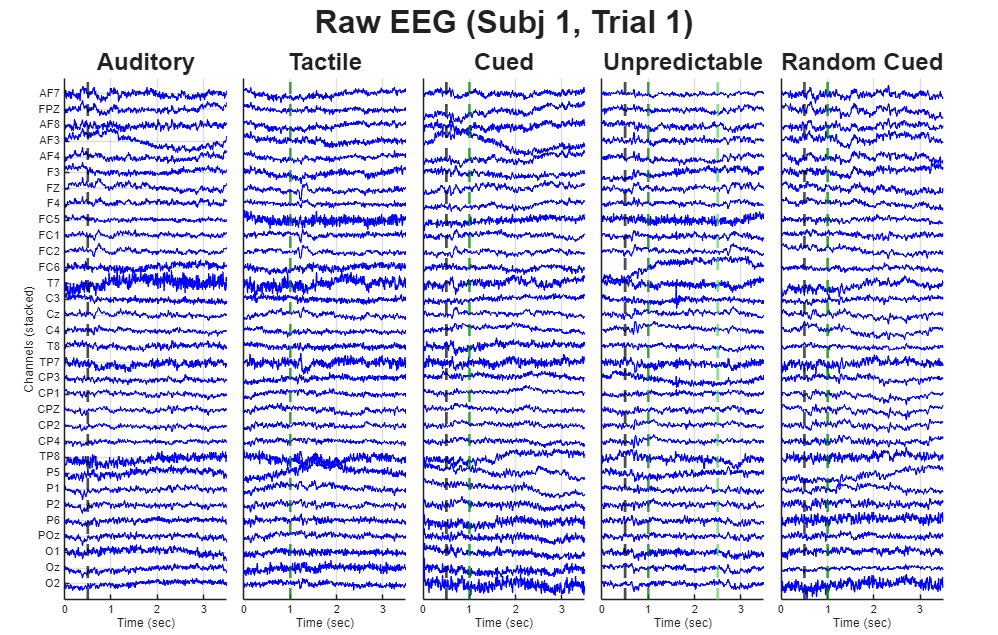

%% Visualizing Specific Trial for a Specific Subject
target_trial = 1; 
target_subject = 1; 

if exist('EEG', 'var') && isfield(EEG, 'chanlocs')
    display_channels_str = {EEG.chanlocs.labels};
else
    display_channels_str = cellstr(num2str((1:size(data_all_conds.BLT{1}, 1))')); 
end

num_channels_plot = length(display_channels_str);
plot_conds = fieldnames(data_all_conds);
num_conds = length(conditions); % Just plotting the base conditions for now

figure('Position',[50 50 2200 1400])
t = tiledlayout(1, num_conds, 'TileSpacing', 'compact', 'Padding', 'compact');
title(t, sprintf('Raw EEG (Subj %d, Trial %d)', target_subject, target_trial), 'FontSize', 24, 'FontWeight', 'bold');

offset = 30; 
tick_positions = (num_channels_plot - (1:num_channels_plot)) * offset;

for c = 1:num_conds
    cond_name = conditions{c};
    
    % Access the cell for the subject, then slice the 3rd dimension for the trial
    data_to_plot = data_all_conds.(cond_name){target_subject}(:, :, target_trial);
    
    nexttile;
    hold on
    for ch = 1:num_channels_plot
        plot(time_ms_eeg, data_to_plot(ch, :) + (num_channels_plot - ch)*offset, 'b', 'LineWidth', 1.0);
    end
    
    if strcmp(cond_name, 'BLT')
        xline(1.0, '--', 'Color', [0 0.5 0], 'LineWidth', 2);
    elseif any(strcmp(cond_name, {'P1','P3'}))
        xline(0.5, 'k--', 'LineWidth', 2);
        xline(1.0, '--', 'Color', [0 0.5 0], 'LineWidth', 2);
    elseif strcmp(cond_name, 'P2')
        xline(0.5, 'k--', 'LineWidth', 2);
        xline(1.0, '--', 'Color', [0 0.5 0], 'LineWidth', 2);
        xline(2.5, '--', 'Color', [0.4 0.8 0.4], 'LineWidth', 2);
    else
        xline(0.5, 'k--', 'LineWidth', 2);
    end
    
    hold off
    xlim([min(time_ms_eeg), max(time_ms_eeg)]); 
    ylim([-offset, num_channels_plot*offset]);
    xlabel('Time (sec)'); 
    
    if c == 1
        ylabel('Channels (stacked)');
        yticks(flip(tick_positions));
        yticklabels(flip(string(display_channels_str)));
    else
        yticks([]);
    end
    if ismember(cond_name, 'BLA')
        plot_name = 'Auditory';
    elseif ismember(cond_name, 'BLT')
        plot_name = 'Tactile';    
    elseif ismember(cond_name, 'P1')
        plot_name = 'Cued';
    elseif ismember(cond_name, 'P2')
        plot_name = 'Unpredictable';
    elseif ismember(cond_name, 'P3')
        plot_name = 'Random Cued';
    end
    title(plot_name, 'FontSize', 18);
    grid on;
end

disp('Calculating averages across trials and subjects...');

Calculating averages across trials and subjects...



cond_names = fieldnames(data_all_conds);
data_subj_avg = struct();
data_grand_avg = struct();
data_grand_std = struct();

for i = 1:length(cond_names)
    c_name = cond_names{i};
    num_subjects = length(data_all_conds.(c_name));
    
    % 1. Average across trials for EACH subject
    % Preallocate [Channels x Time x Subjects]
    subj_avg_matrix = zeros(num_ch, length(time_ms_eeg), num_subjects);
    
    for s = 1:num_subjects
        % Average across dim 3 (trials)
        subj_avg_matrix(:,:,s) = mean(data_all_conds.(c_name){s}, 3, 'omitnan');
    end
    data_subj_avg.(c_name) = subj_avg_matrix;
    
    % 2. Average across subjects (Grand Average)
    data_grand_avg.(c_name) = mean(subj_avg_matrix, 3, 'omitnan');
    
    % 3. Standard Deviation across subjects (for shaded error bars)
    data_grand_std.(c_name) = std(subj_avg_matrix, 0, 3, 'omitnan');
end

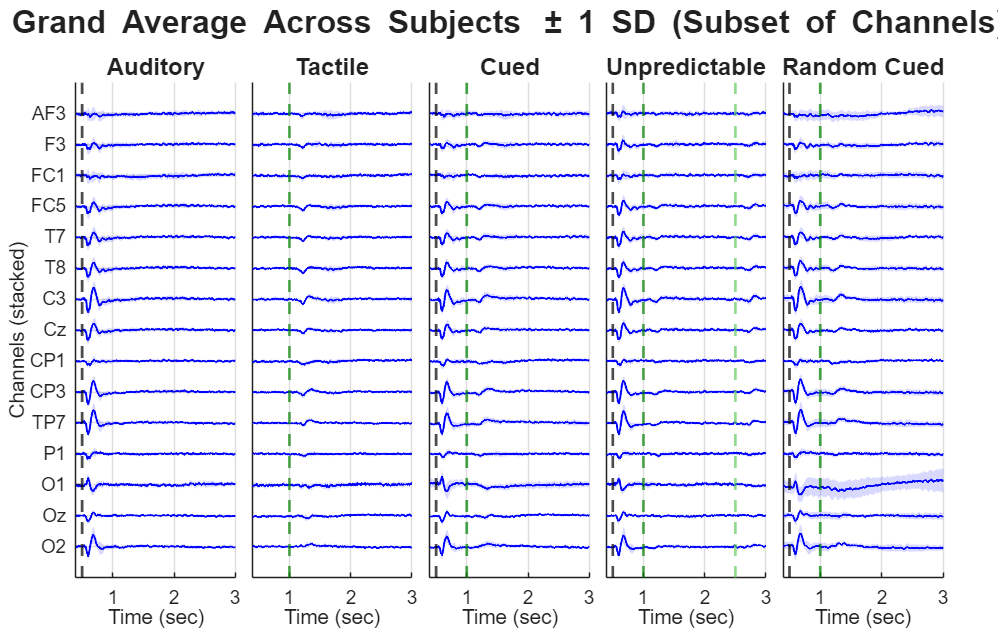

%% Visualizing Grand Average with STD Shading
channels_to_plot = {'AF3', 'F3', 'Fz', 'FC1', 'FC5', 'T7', 'T8', 'C3', 'Cz', 'CP1', 'CP3', 'TP7', 'P1', 'O1', 'Oz', 'O2'};

[~, chan_idx] = ismember(channels_to_plot, display_channels_str);
valid_mask = chan_idx > 0;
chan_idx = chan_idx(valid_mask);
display_channels_str = channels_to_plot(valid_mask);

num_channels_plot = length(display_channels_str);
num_conds = length(conditions); 

figure('Position',[50 50 2200 1400])
t = tiledlayout(1, num_conds, 'TileSpacing', 'compact', 'Padding', 'compact');
title(t, 'Grand Average Across Subjects \pm 1 SD (Subset of Channels)', 'FontSize', 24, 'FontWeight', 'bold');

offset = 15; 
tick_positions = (num_channels_plot - (1:num_channels_plot)) * offset;
time_fill = [time_ms_eeg, fliplr(time_ms_eeg)]; % X-axis for shading

for c = 1:num_conds
    cond_name = conditions{c};
    
    nexttile;
    hold on
    
    for ch = 1:num_channels_plot
        actual_ch = chan_idx(ch);
        y_shift = (num_channels_plot - ch) * offset;
        
        % Extract mean and std for this specific channel
        mu = data_grand_avg.(cond_name)(actual_ch, :) + y_shift;
        sigma = data_grand_std.(cond_name)(actual_ch, :);
        
        % Create boundaries for the shaded standard deviation
        y_bound = [mu + sigma, fliplr(mu - sigma)];
        
        % Plot Shaded STD Area first (so it sits behind the line)
        fill(time_fill, y_bound, 'b', 'FaceAlpha', 0.15, 'EdgeColor', 'none', 'HandleVisibility', 'off');
        
        % Plot Mean Line
        plot(time_ms_eeg, mu, 'b', 'LineWidth', 1.5);
    end
    
    % Add Vertical Event Lines
    if strcmp(cond_name, 'BLT')
        xline(1.0, '--', 'Color', [0 0.5 0], 'LineWidth', 2);
    elseif any(strcmp(cond_name, {'P1','P3'}))
        xline(0.5, 'k--', 'LineWidth', 2);
        xline(1.0, '--', 'Color', [0 0.5 0], 'LineWidth', 2);
    elseif strcmp(cond_name, 'P2')
        xline(0.5, 'k--', 'LineWidth', 2);
        xline(1.0, '--', 'Color', [0 0.5 0], 'LineWidth', 2);
        xline(2.5, '--', 'Color', [0.4 0.8 0.4], 'LineWidth', 2);
    else
        xline(0.5, 'k--', 'LineWidth', 2);
    end
    
    hold off
    xlim([0.4, 3]); 
    ylim([-offset, num_channels_plot*offset]);
    xlabel('Time (sec)'); 
    
    if c == 1
        ylabel('Channels (stacked)');
        yticks(flip(tick_positions));
        yticklabels(flip(string(display_channels_str)));
    else
        yticks([]); 
    end
    
    set(gca,'FontSize',14);
    if ismember(cond_name, 'BLA')
        plot_name = 'Auditory';
    elseif ismember(cond_name, 'BLT')
        plot_name = 'Tactile';    
    elseif ismember(cond_name, 'P1')
        plot_name = 'Cued';
    elseif ismember(cond_name, 'P2')
        plot_name = 'Unpredictable';
    elseif ismember(cond_name, 'P3')
        plot_name = 'Random Cued';
    end
    title(plot_name, 'FontSize', 18);
    grid on;
end

## 1.3 Calculating the trail averaged signal per condition

disp('Calculating trial averages...');

Calculating trial averages...


cond_names = fieldnames(data_all_conds);
data_avg = struct();

for i = 1:length(cond_names)
    c_name = cond_names{i};
    % Average across the 3rd dimension (trials), ignoring NaNs if any exist
    data_avg.(c_name) = mean(data_all_conds.(c_name), 3, 'omitnan');
end


## Visualizing Trial-Averaged EEG Across Time (Subplots per Condition)

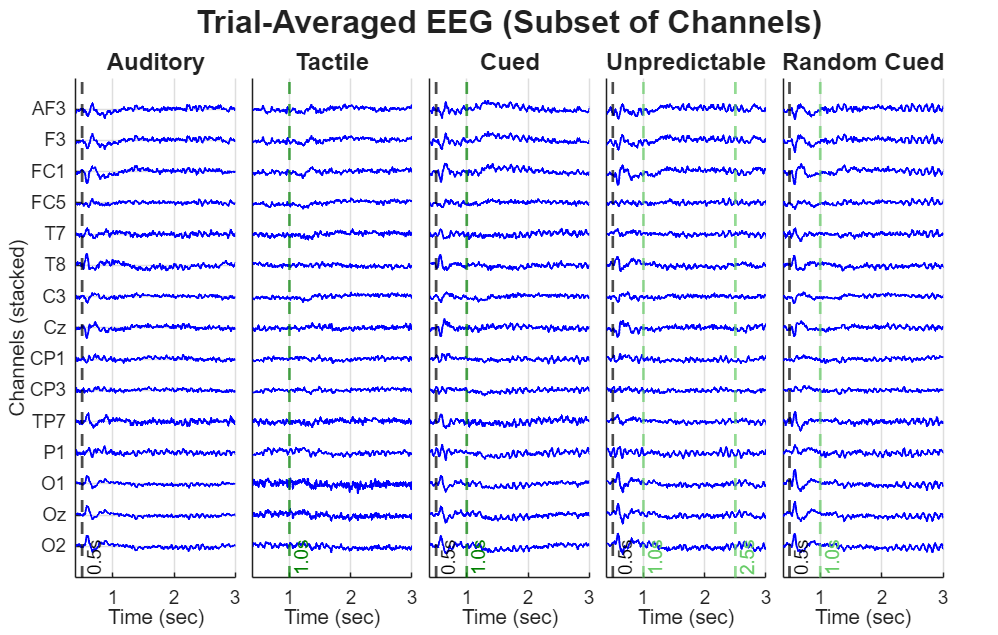

%% Visualizing Specific Channels Trial-Averaged Across Time

% 1. Define the specific channels you want to plot
channels_to_plot = {'AF3', 'F3', 'Fz', 'FC1', 'FC5', 'T7', 'T8', 'C3', 'Cz', 'CP1', 'CP3', 'TP7', 'P1', 'O1', 'Oz', 'O2'};

% Safely extract all 32 channel labels 
if exist('EEG', 'var') && isfield(EEG, 'chanlocs')
    all_channels_str = {EEG.chanlocs.labels};
else
    % Fallback if EEG structure isn't in the workspace (assumes 1-32 string array)
    all_channels_str = cellstr(num2str((1:size(data_all_conds.BLT, 1))')); 
end

% 2. Find the indices of the requested channels within the full 32-channel list
[~, chan_idx] = ismember(channels_to_plot, all_channels_str);

% Safety check: remove any channels from the list that weren't found in your dataset (index 0)
valid_mask = chan_idx > 0;
chan_idx = chan_idx(valid_mask);
display_channels_str = channels_to_plot(valid_mask);

num_channels_plot = length(display_channels_str);
display_channels = 1:1:num_channels_plot;
num_conds = length(conditions); 

% Widen the figure to comfortably fit side-by-side plots
figure('Position',[50 50 2200 1400])
t = tiledlayout(1, num_conds, 'TileSpacing', 'compact', 'Padding', 'compact');
title(t, 'Trial-Averaged EEG (Subset of Channels)', 'FontSize', 24, 'FontWeight', 'bold');

% Offset: adjust this (e.g., 10 to 30) based on how squished the averaged traces look
offset = 15; 
tick_positions = (num_channels_plot - display_channels) * offset;

% Custom colors for the event lines
dark_green  = [0 0.5 0];
light_green = [0.4 0.8 0.4];

% Loop through all conditions to generate the tiles dynamically
for c = 1:num_conds
    cond_name = conditions{c};
    
    % --- UPDATED DATA EXTRACTION ---
    % Average across the 3rd dimension (trials), but ONLY for the chan_idx rows!
    data_to_plot = data_avg.(cond_name)(chan_idx, :, :);
    
    nexttile;
    hold on
    
    % 1. Plot the Sub-selected Channels
    for ch = 1:num_channels_plot
        % Stack channels vertically and strictly use blue ('b')
        plot(time_ms_eeg, data_to_plot(ch, :) + (num_channels_plot - ch)*offset, 'b', 'LineWidth', 1.5);
    end
    
    % 2. Add Vertical Event Lines
    % All conditions get a dashed vertical line at time 0.5 sec
    if strcmp(cond_name, 'BLT')
        xline(1.0, '--', '1.0s', 'Color', dark_green, 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
    else
        xline(0.5, 'k--', '0.5s', 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
    end
    
    % Condition-specific event lines
    if ismember(cond_name, 'P1')
        xline(1.0, '--', '1.0s', 'Color', dark_green, 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
        
    elseif strcmp(cond_name, 'P2')
        xline(1.0, '--', '1.0s', 'Color', light_green, 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
        xline(2.5, '--', '2.5s', 'Color', light_green, 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
        
    elseif strcmp(cond_name, 'P3')
        xline(1.0, '--', '1.0s', 'Color', light_green, 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
    end
    
    hold off
    
    % Fit the X-axis strictly to our cropped time window
    xlim([0.4, 3]); 
    ylim([-offset, num_channels_plot*offset]);
    
    xlabel('Time (sec)'); 
    
    % Only show Y-axis labels on the very first (leftmost) plot
    if c == 1
        ylabel('Channels (stacked)');
        yticks(flip(tick_positions));
        yticklabels(flip(string(display_channels_str)));
    else
        yticks([]); % Remove ticks for subsequent plots to maximize data visibility
    end
    
    set(gca,'FontSize',14);
    if ismember(cond_name, 'BLA')
        plot_name = 'Auditory';
    elseif ismember(cond_name, 'BLT')
        plot_name = 'Tactile';    
    elseif ismember(cond_name, 'P1')
        plot_name = 'Cued';
    elseif ismember(cond_name, 'P2')
        plot_name = 'Unpredictable';
    elseif ismember(cond_name, 'P3')
        plot_name = 'Random Cued';
    end
    title(sprintf('%s', plot_name), 'FontSize', 18);
    grid on;
end

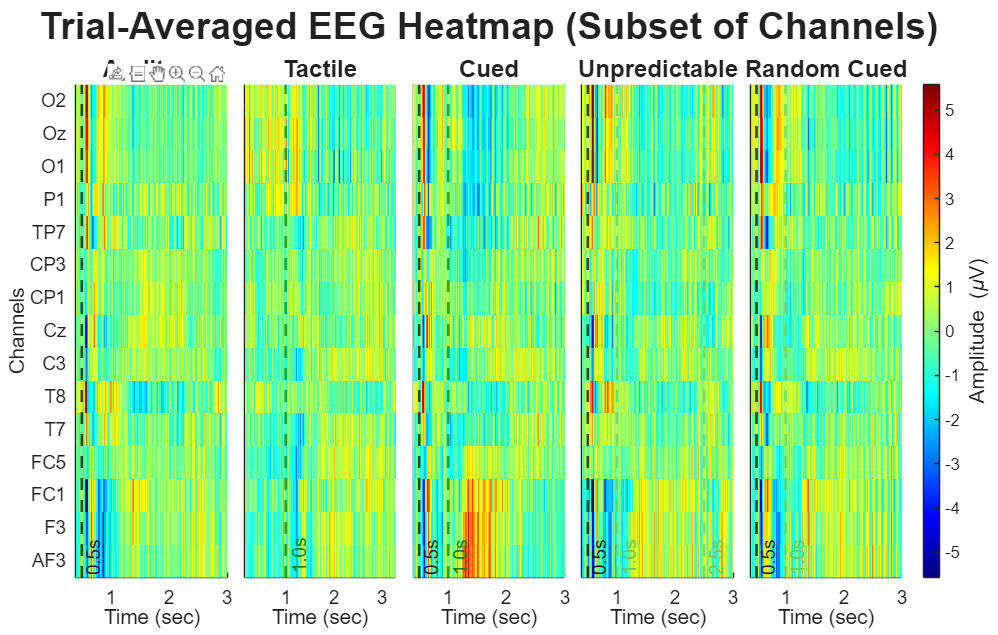

% 1. Define the specific channels you want to plot
channels_to_plot = {'AF3', 'F3', 'Fz', 'FC1', 'FC5', 'T7', 'T8', 'C3', 'Cz', 'CP1', 'CP3', 'TP7', 'P1', 'O1', 'Oz', 'O2'};

% Safely extract all 32 channel labels 
if exist('EEG', 'var') && isfield(EEG, 'chanlocs')
    all_channels_str = {EEG.chanlocs.labels};
else
    % Fallback if EEG structure isn't in the workspace
    all_channels_str = cellstr(num2str((1:size(data_all_conds.BLT, 1))')); 
end

% 2. Find the indices of the requested channels within the full 32-channel list
[~, chan_idx] = ismember(channels_to_plot, all_channels_str);

% Safety check: remove any channels from the list that weren't found
valid_mask = chan_idx > 0;
chan_idx = chan_idx(valid_mask);
display_channels_str = channels_to_plot(valid_mask);

num_channels_plot = length(display_channels_str);
num_conds = length(conditions); 

% --- NEW: Determine Global Color Limits ---
% We need the max absolute amplitude across ALL conditions so the heatmaps share a uniform color scale
global_max = 0;
for c = 1:num_conds
    cond_name = conditions{c};
    % Extract 2D data (assuming data_avg is already [Channels x Time])
    temp_data = data_avg.(cond_name)(chan_idx, :); 
    global_max = max(global_max, max(abs(temp_data(:))));
end
% Set a reasonable color limit (you can multiply global_max by 0.8 to saturate and highlight peaks)
color_limits = [-global_max, global_max] * 0.8; 

% Widen the figure to comfortably fit side-by-side plots
figure('Position',[50 50 2200 1400])
t = tiledlayout(1, num_conds, 'TileSpacing', 'compact', 'Padding', 'compact');
title(t, 'Trial-Averaged EEG Heatmap (Subset of Channels)', 'FontSize', 28, 'FontWeight', 'bold');

% Custom colors for the event lines
dark_green  = [0 0.5 0];
light_green = [0.4 0.8 0.4];

% Loop through all conditions to generate the tiles dynamically
for c = 1:num_conds
    cond_name = conditions{c};
    
    % --- Extract 2D Data ---
    % Make sure it is exactly a 2D matrix [Channels x Time]
    data_to_plot = squeeze(data_avg.(cond_name)(chan_idx, :));
    
    nexttile;
    hold on;
    
    % 1. Plot the Heatmap
    % imagesc scales the matrix data to the colormap
    imagesc(time_ms_eeg, 1:num_channels_plot, data_to_plot);
    
    % Apply the global color limits so all subplots are directly comparable
    clim(color_limits); 
    
    % 2. Add Vertical Event Lines
    % All conditions get a dashed vertical line at time 0.5 sec EXCEPT BLT
    if strcmp(cond_name, 'BLT')
        xline(1.0, '--', '1.0s', 'Color', dark_green, 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
    else
        xline(0.5, 'k--', '0.5s', 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
    end
    
    % Condition-specific event lines
    if ismember(cond_name, 'P1')
        xline(1.0, '--', '1.0s', 'Color', dark_green, 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
        
    elseif strcmp(cond_name, 'P2')
        xline(1.0, '--', '1.0s', 'Color', light_green, 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
        xline(2.5, '--', '2.5s', 'Color', light_green, 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
        
    elseif strcmp(cond_name, 'P3')
        xline(1.0, '--', '1.0s', 'Color', light_green, 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
    end
    
    hold off;
    
    % Fit the X-axis strictly to our cropped time window
    xlim([0.4, 3]); 
    ylim([0.5, num_channels_plot + 0.5]); % Fit Y-axis perfectly to the rows
    
    xlabel('Time (sec)'); 
    
    % Y-Axis formatting
    if c == 1
        ylabel('Channels');
        yticks(1:num_channels_plot);
        yticklabels(display_channels_str);
    else
        yticks([]); % Remove ticks for subsequent plots to maximize data visibility
    end
    
    % Ensure the Y-axis isn't flipped upside down (standard for imagesc)
    set(gca, 'YDir', 'normal', 'FontSize', 14);
    
    % Custom Titles
    if ismember(cond_name, 'BLA')
        plot_name = 'Auditory';
    elseif ismember(cond_name, 'BLT')
        plot_name = 'Tactile';    
    elseif ismember(cond_name, 'P1')
        plot_name = 'Cued';
    elseif ismember(cond_name, 'P2')
        plot_name = 'Unpredictable';
    elseif ismember(cond_name, 'P3')
        plot_name = 'Random Cued';
    else
        plot_name = cond_name;
    end
    title(sprintf('%s', plot_name), 'FontSize', 18);
    
end

% Use a divergent colormap like 'jet' or 'parula'
colormap('jet'); 
cb = colorbar;
cb.Layout.Tile = 'east'; % Attaches the colorbar to the right side of the entire layout
cb.Label.String = 'Amplitude (\muV)';
cb.Label.FontSize = 16;

## 1.4 Generating synthetic Cued, Unpredictable and Random Cued

% Cued
mean_BLA = data_avg.BLA;
mean_BLT = data_avg.BLT;

% Sum the averaged signals per channel
data_avg.P1_syn = mean_BLA + mean_BLT;

fprintf('Generated Synthetic P1 shape: %d channels x %d time points\n', ...
        size(data_avg.P1_syn, 1), size(data_avg.P1_syn, 2));

Generated Synthetic P1 shape: 32 channels x 1792 time points


data_avg.P2_syn = data_avg.P1_syn + data_avg.P2_2000;

fprintf('Generated Synthetic P2 shape: %d channels x %d time points\n', ...
        size(data_avg.P2_syn, 1), size(data_avg.P2_syn, 2));

Generated Synthetic P2 shape: 32 channels x 1792 time points



data_avg.P3_syn = data_avg.P1_syn + data_avg.P3_missing;

fprintf('Generated Synthetic P3 shape: %d channels x %d time points\n', ...
        size(data_avg.P3_syn, 1), size(data_avg.P3_syn, 2));

Generated Synthetic P3 shape: 32 channels x 1792 time points


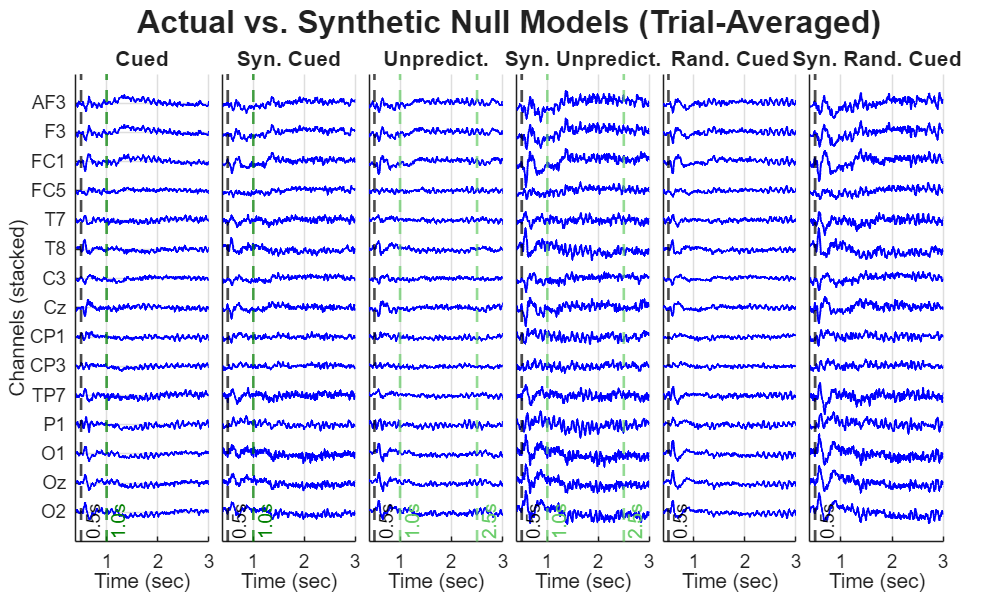

% 1. Define the specific channels you want to plot
channels_to_plot = {'AF3', 'F3', 'Fz', 'FC1', 'FC5', 'T7', 'T8', 'C3', 'Cz', 'CP1', 'CP3', 'TP7', 'P1', 'O1', 'Oz', 'O2'};

% Safely extract all 32 channel labels 
if exist('EEG', 'var') && isfield(EEG, 'chanlocs')
    all_channels_str = {EEG.chanlocs.labels};
else
    % Fallback if EEG structure isn't in the workspace
    all_channels_str = cellstr(num2str((1:size(data_avg.P1, 1))')); 
end

% 2. Find the indices of the requested channels within the full list
[~, chan_idx] = ismember(channels_to_plot, all_channels_str);
valid_mask = chan_idx > 0;
chan_idx = chan_idx(valid_mask);
display_channels_str = channels_to_plot(valid_mask);

num_channels_plot = length(display_channels_str);
display_channels = 1:1:num_channels_plot;

% --- NEW: Define the exact sequence of conditions you want to compare ---
compare_conds = {'P1', 'P1_syn', 'P2', 'P2_syn', 'P3', 'P3_syn'};
num_conds = length(compare_conds); 

% Widen the figure to comfortably fit the 4 side-by-side plots
figure('Position',[50 50 2000 1200])
t = tiledlayout(1, num_conds, 'TileSpacing', 'compact', 'Padding', 'compact');
title(t, 'Actual vs. Synthetic Null Models (Trial-Averaged)', 'FontSize', 24, 'FontWeight', 'bold');

% Vertical offset for stacking
offset = 15; 
tick_positions = (num_channels_plot - display_channels) * offset;

% Custom colors for the event lines
dark_green  = [0 0.5 0];
light_green = [0.4 0.8 0.4];

% Loop through the specific comparison conditions
for c = 1:num_conds
    cond_name = compare_conds{c};
    
    % Extract the 2D matrix for the specific channels
    data_to_plot = data_avg.(cond_name)(chan_idx, :);
    
    nexttile;
    hold on;
    
    % 1. Plot the Sub-selected Channels
    for ch = 1:num_channels_plot
        % Stack channels vertically and use blue ('b')
        plot(time_ms_eeg, data_to_plot(ch, :) + (num_channels_plot - ch)*offset, 'b', 'LineWidth', 1.5);
    end
    
    % 2. Add Vertical Event Lines
    % All conditions get the auditory onset at 0.5s
    xline(0.5, 'k--', '0.5s', 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
    
    % Add the tactile event lines based on whether it is P1 or P2 (synthetic or actual)
    if startsWith(cond_name, 'P1')
        xline(1.0, '--', '1.0s', 'Color', dark_green, 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
    elseif startsWith(cond_name, 'P2')
        xline(1.0, '--', '1.0s', 'Color', light_green, 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
        xline(2.5, '--', '2.5s', 'Color', light_green, 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
    end
    
    % --- NEW: Set Shorthand Titles ---
    if strcmp(cond_name, 'P1')
        plot_title = 'Cued';
    elseif strcmp(cond_name, 'P1_syn')
        plot_title = 'Syn. Cued';
    elseif strcmp(cond_name, 'P2')
        plot_title = 'Unpredict.';
    elseif strcmp(cond_name, 'P2_syn')
        plot_title = 'Syn. Unpredict.';
    elseif strcmp(cond_name, 'P3')
        plot_title = 'Rand. Cued';
    elseif strcmp(cond_name, 'P3_syn')
        plot_title = 'Syn. Rand. Cued';
    end
    
    hold off;
    
    % Fit the X-axis strictly to the relevant time window
    xlim([0.4, 3]); 
    ylim([-offset, num_channels_plot*offset]);
    
    xlabel('Time (sec)'); 
    
    % Only show Y-axis labels on the very first (leftmost) plot
    if c == 1
        ylabel('Channels (stacked)');
        yticks(flip(tick_positions));
        yticklabels(flip(string(display_channels_str)));
    else
        yticks([]); % Remove ticks for subsequent plots to maximize data visibility
    end
    
    set(gca,'FontSize',14);
    title(plot_title, 'FontSize', 16);
    grid on;
end

## 1.5 Calculate residuals, the difference between natural conditions and synthetic conditions

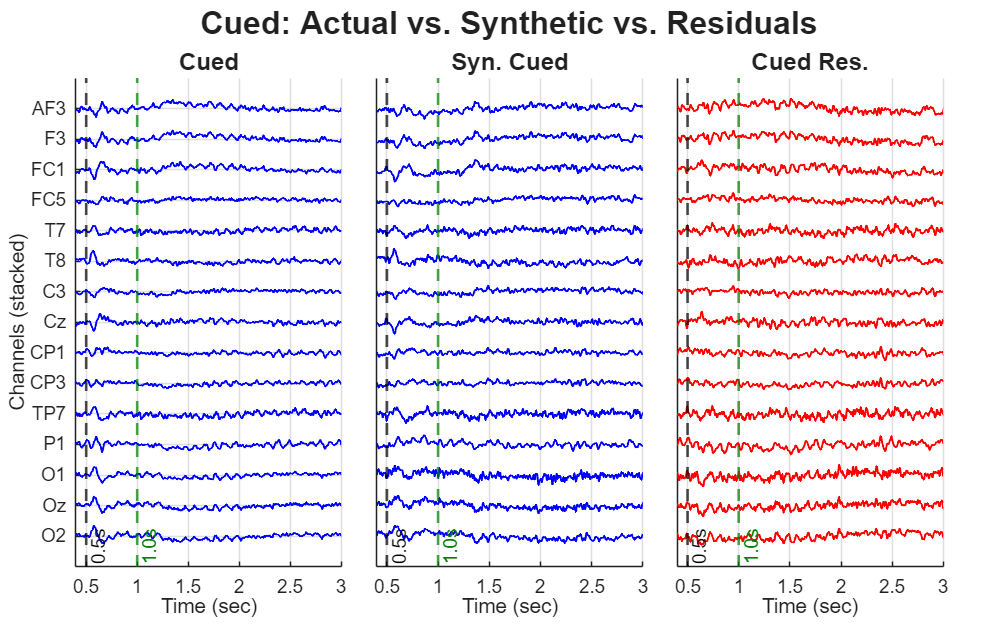

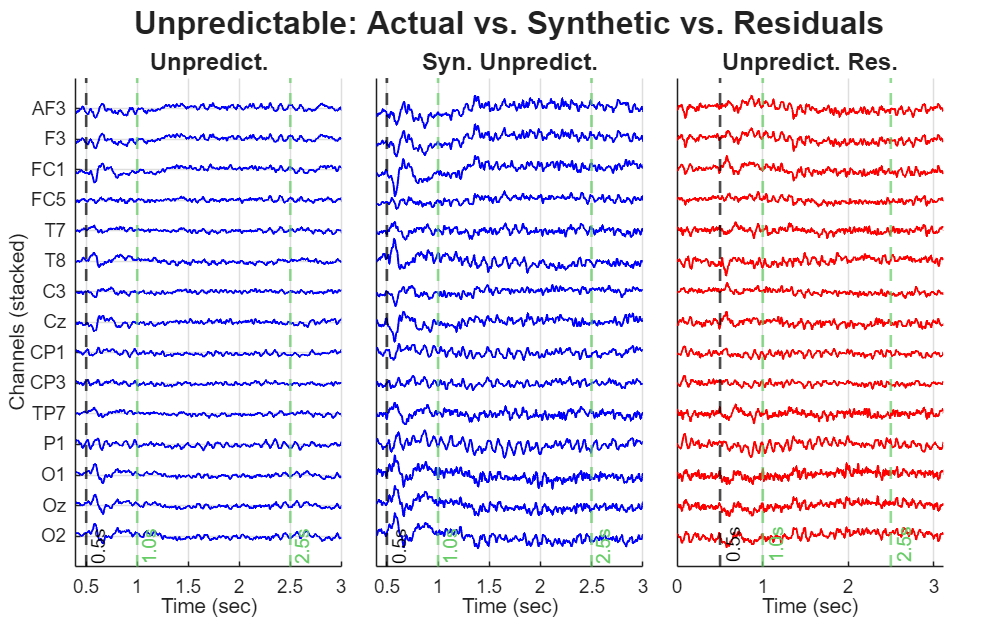

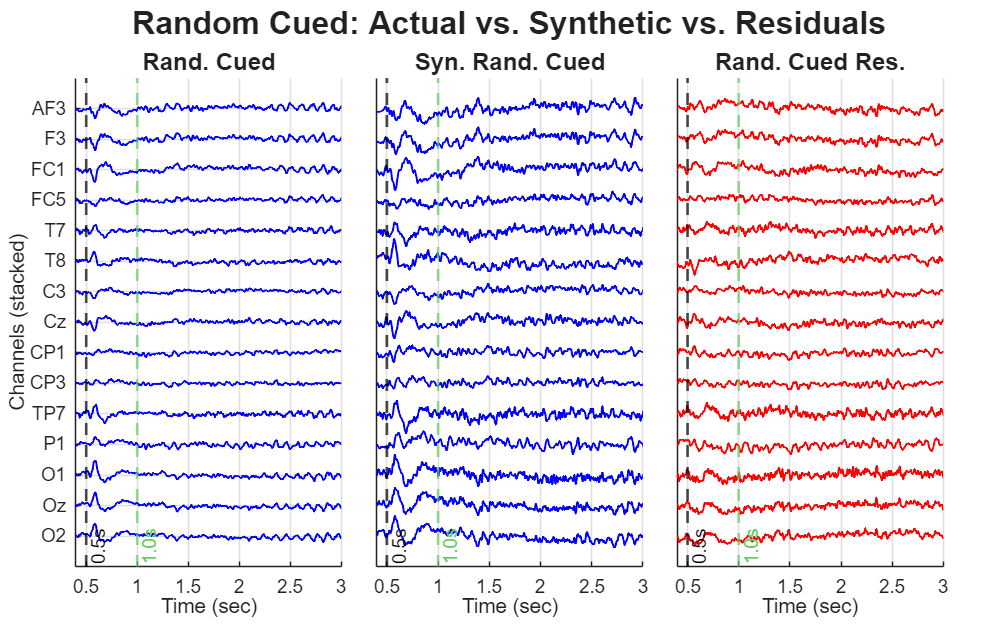

% Store the residuals for further analysis
data_avg.P1_res = data_avg.P1 - data_avg.P1_syn;
data_avg.P2_res = data_avg.P2 - data_avg.P2_syn;
data_avg.P3_res = data_avg.P3 - data_avg.P3_syn;
% 1. Define the specific channels you want to plot
channels_to_plot = {'AF3', 'F3', 'Fz', 'FC1', 'FC5', 'T7', 'T8', 'C3', 'Cz', 'CP1', 'CP3', 'TP7', 'P1', 'O1', 'Oz', 'O2'};

% Safely extract all 32 channel labels 
if exist('EEG', 'var') && isfield(EEG, 'chanlocs')
    all_channels_str = {EEG.chanlocs.labels};
else
    all_channels_str = cellstr(num2str((1:size(data_avg.P1, 1))')); 
end

% 2. Find the indices of the requested channels within the full list
[~, chan_idx] = ismember(channels_to_plot, all_channels_str);
valid_mask = chan_idx > 0;
chan_idx = chan_idx(valid_mask);
display_channels_str = channels_to_plot(valid_mask);

num_channels_plot = length(display_channels_str);
display_channels = 1:1:num_channels_plot;

% Vertical offset for stacking
offset = 15; 
tick_positions = (num_channels_plot - display_channels) * offset;

% Custom colors for the event lines
dark_green  = [0 0.5 0];
light_green = [0.4 0.8 0.4];

% --- NEW: Group definitions for the outer loop ---
condition_groups = {'P1', 'P2', 'P3'};
group_names = {'Cued', 'Unpredictable', 'Random Cued'};

% Outer loop: Create one figure per condition group
for g = 1:length(condition_groups)
    base_cond = condition_groups{g};
    group_title = group_names{g};
    
    % Define the 3 specific variants for this group's subplots
    plot_conds = {base_cond, [base_cond '_syn'], [base_cond '_res']};
    plot_titles = {sprintf('Actual %s', base_cond), ...
                   sprintf('Syn. %s', base_cond), ...
                   sprintf('%s Residuals', base_cond)};
                   
    % Set up the figure for this specific group
    figure('Position',[50 50 1600 1000])
    t = tiledlayout(1, 3, 'TileSpacing', 'compact', 'Padding', 'compact');
    title(t, sprintf('%s: Actual vs. Synthetic vs. Residuals', group_title), 'FontSize', 24, 'FontWeight', 'bold');
    
    % Inner loop: Generate the 3 side-by-side tiles
    for c = 1:3
        cond_name = plot_conds{c};
        if strcmp(cond_name, 'P1')
            plot_title = 'Cued';
        elseif strcmp(cond_name, 'P1_syn')
            plot_title = 'Syn. Cued';
        elseif strcmp(cond_name, 'P1_res')
            plot_title = 'Cued Res.';
        elseif strcmp(cond_name, 'P2')
            plot_title = 'Unpredict.';
        elseif strcmp(cond_name, 'P2_syn')
            plot_title = 'Syn. Unpredict.';
        elseif strcmp(cond_name, 'P2_res')
            plot_title = 'Unpredict. Res.';            
        elseif strcmp(cond_name, 'P3')
            plot_title = 'Rand. Cued';
        elseif strcmp(cond_name, 'P3_syn')
            plot_title = 'Syn. Rand. Cued';
        elseif strcmp(cond_name, 'P3_res')
            plot_title = 'Rand. Cued Res.';            
        end
        
        % Extract the 2D matrix for the specific channels
        data_to_plot = data_avg.(cond_name)(chan_idx, :);
        
        nexttile;
        hold on;
        
        % 1. Plot the Sub-selected Channels
        for ch = 1:num_channels_plot
            % Stack channels vertically. 
            % Use blue for Actual/Synthetic, and red for Residuals to make them pop!
            plot_color = 'b';
            if c == 3 
                plot_color = 'r'; 
            end
            
            plot(time_ms_eeg, data_to_plot(ch, :) + (num_channels_plot - ch)*offset, plot_color, 'LineWidth', 1.5);
        end
        
        % 2. Add Vertical Event Lines
        xline(0.5, 'k--', '0.5s', 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
        
        % Add the tactile event lines based on the base condition
        if strcmp(base_cond, 'P1')
            xline(1.0, '--', '1.0s', 'Color', dark_green, 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
        elseif strcmp(base_cond, 'P2')
            xline(1.0, '--', '1.0s', 'Color', light_green, 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
            xline(2.5, '--', '2.5s', 'Color', light_green, 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
        elseif strcmp(base_cond, 'P3')
            xline(1.0, '--', '1.0s', 'Color', light_green, 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
        end

        hold off;
        
        % Fit the X-axis strictly to the relevant time window
        xlim([0.4, 3]); 
        ylim([-offset, num_channels_plot*offset]);
        
        xlabel('Time (sec)'); 
        
        % Only show Y-axis labels on the very first (leftmost) plot
        if c == 1
            ylabel('Channels (stacked)');
            yticks(flip(tick_positions));
            yticklabels(flip(string(display_channels_str)));
        else
            yticks([]); % Remove ticks for subsequent plots
        end
        
        set(gca,'FontSize',14);
        title(plot_title, 'FontSize', 18);
        grid on;
    end
end

## 2.0 PCA per condition

%% 2.0 PCA per condition
% Mapping: ch x time -> comp x time
disp('Performing PCA per condition...');

Performing PCA per condition...


pca_results = struct();
cond_names = fieldnames(data_avg);
for i = 1:length(cond_names)
    c_name = cond_names{i};
    X = data_avg.(c_name); % Size: [num_ch x time]
    
    % Mean center the data across time for PCA
    % X_centered = X - mean(X, 2);
    
    % Perform PCA. MATLAB's pca() function expects [observations x variables].
    % We want components from channels, so we treat time points as observations 
    % and channels as variables, meaning we transpose X_centered.
    [coeff, score, latent, tsquared, explained] = pca(X');
    
    % coeff is [ch x comp] (Spatial filters)
    % score is [time x comp] (Component time courses)
    
    pca_results.(c_name).coeff = coeff;
    pca_results.(c_name).comp_time = score'; % Transpose to match your desired [comp x time]
    pca_results.(c_name).explained = explained;
end

intrisic_dim = struct();

% Create the master figure for the tiled layout
figure('Position', [50 50 1600 1200]); 
tiledlayout(5, 3, 'TileSpacing', 'compact', 'Padding', 'compact');

for i = 1:length(cond_names)
    c_name = cond_names{i};
    X = data_avg.(c_name); % Size: [num_ch x time]
    
    % The data's rank for the condition
    intrisic_dim.(c_name).rank = rank(X);

    % Marchenko–Pastur threshold (Added real() to prevent complex warnings)
    eig_vals = real(eig(cov(X'))); 
    [N, T] = size(X);
    Q = T / N;
    sigma2 = mean(eig_vals);           
    lambda_max = sigma2 * (1 + sqrt(1/Q))^2;
    
    % Find number of components above the MP threshold
    num_sig_components = sum(eig_vals > lambda_max);
    intrisic_dim.(c_name).num_sig_components = num_sig_components;

    fprintf('\n[%s] Marchenko–Pastur suggests keeping %d PCs\n', c_name, num_sig_components);
    
    % Move to the next tile in the 5x2 grid
    nexttile;
    
    % Call the updated function, passing the condition name for the title
    [num_factors, map_values] = velicer_map(X', c_name);
    
    intrisic_dim.(c_name).num_factors = num_factors;
end


[BLA] Marchenko–Pastur suggests keeping 3 PCs


Velicer's MAP Test recommends retaining 9 factors.



[BLT] Marchenko–Pastur suggests keeping 4 PCs


Velicer's MAP Test recommends retaining 8 factors.



[P1] Marchenko–Pastur suggests keeping 3 PCs


Velicer's MAP Test recommends retaining 10 factors.



[P2] Marchenko–Pastur suggests keeping 3 PCs


Velicer's MAP Test recommends retaining 6 factors.



[P2_500] Marchenko–Pastur suggests keeping 3 PCs


Velicer's MAP Test recommends retaining 10 factors.



[P2_2000] Marchenko–Pastur suggests keeping 3 PCs


Velicer's MAP Test recommends retaining 7 factors.



[P3] Marchenko–Pastur suggests keeping 3 PCs


Velicer's MAP Test recommends retaining 9 factors.



[P3_500] Marchenko–Pastur suggests keeping 3 PCs


Velicer's MAP Test recommends retaining 9 factors.



[P3_missing] Marchenko–Pastur suggests keeping 3 PCs


Velicer's MAP Test recommends retaining 10 factors.



[P1_syn] Marchenko–Pastur suggests keeping 3 PCs


Velicer's MAP Test recommends retaining 8 factors.



[P2_syn] Marchenko–Pastur suggests keeping 3 PCs


Velicer's MAP Test recommends retaining 10 factors.



[P3_syn] Marchenko–Pastur suggests keeping 3 PCs


Velicer's MAP Test recommends retaining 12 factors.



[P1_res] Marchenko–Pastur suggests keeping 4 PCs


Velicer's MAP Test recommends retaining 13 factors.



[P2_res] Marchenko–Pastur suggests keeping 3 PCs


Velicer's MAP Test recommends retaining 13 factors.



[P3_res] Marchenko–Pastur suggests keeping 3 PCs


Velicer's MAP Test recommends retaining 11 factors.


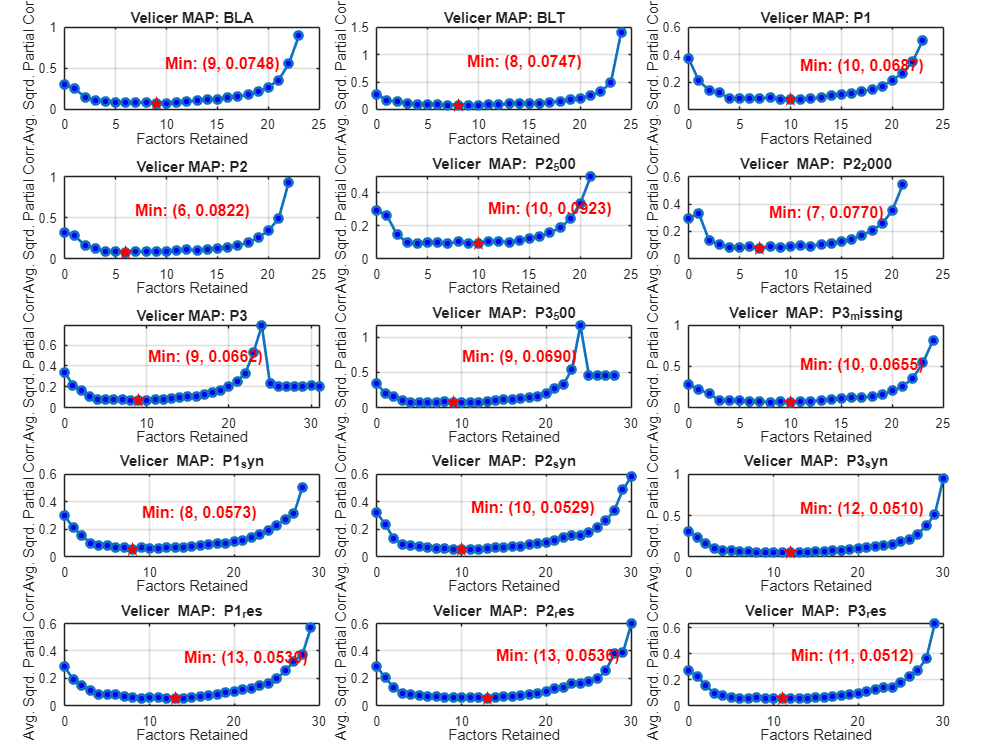

hold off;

function [num_factors, map_values] = velicer_map(data, cond_title)
% VELICER_MAP Determines the number of factors to retain using Velicer's MAP test.

    % 1. Compute the correlation matrix
    R = corrcoef(data);
    p = size(R, 1);
    
    % 2. Perform Eigenvalue Decomposition
    [eigvec, eigval_mat] = eig(R);
    
    % FIX: Wrap in real() to drop floating-point imaginary artifacts
    eigval = real(diag(eigval_mat));
    
    % Sort eigenvalues and eigenvectors in descending order
    [eigval, idx] = sort(eigval, 'descend');
    eigvec = real(eigvec(:, idx)); 
    
    % Initialize array to store the MAP values
    map_values = zeros(1, p);
    
    % 3. Step 0: Calculate average squared correlation (no factors partialled out)
    R_off_diag = R - eye(p);
    map_values(1) = sum(R_off_diag(:).^2) / (p * (p - 1));
    
    % 4. Loop to partial out 1 to p-1 components
    for m = 1:(p-1)
        A = eigvec(:, 1:m) * diag(sqrt(eigval(1:m)));
        part_cov = R - (A * A');
        
        d = diag(part_cov);
        inv_sqrt_d = diag(1 ./ sqrt(d));
        R_partial = inv_sqrt_d * part_cov * inv_sqrt_d;
        
        R_partial_off = R_partial - eye(p);
        map_values(m+1) = sum(R_partial_off(:).^2) / (p * (p - 1));
    end
    
    % 5. Find the minimum MAP value
    [min_val, min_idx] = min(map_values);
    num_factors = min_idx - 1;
    
    % 6. Plotting (Modified to use current active tile instead of a new figure)
    
    plot(0:(p-1), map_values, '-o', 'LineWidth', 2, 'MarkerFaceColor', 'b');
    hold on;
    % Highlight minimum
    plot(num_factors, map_values(min_idx), 'rp', 'MarkerSize', 10, 'MarkerFaceColor', 'r'); 
    
    coordinate_text = sprintf('  Min: (%d, %.4f)', num_factors, min_val);
    
    % Adjusted Y-coordinate and font sizes to fit nicely inside the subplots
    text(num_factors, max(map_values)*0.5, coordinate_text, ...
        'VerticalAlignment', 'bottom', ...
        'HorizontalAlignment', 'left', ...
        'FontSize', 12, ...
        'FontWeight', 'bold', ...
        'Color', 'r');
        
    xlabel('Factors Retained', 'FontSize', 10);
    ylabel('Avg. Sqrd. Partial Corr.', 'FontSize', 10);
    
    % Dynamic Title
    if nargin > 1
        title(sprintf('Velicer MAP: %s', char(cond_title)), 'FontSize', 14);
    else
        title('Velicer''s MAP Test', 'FontSize', 14);
    end
    
    set(gca,'FontSize', 10);
    grid on;
    hold off;
    
    % Output the result to the console
    fprintf('Velicer''s MAP Test recommends retaining %d factors.\n', num_factors);
end

## Visualizing Top 4 Principal Components Across Time (Subplots per Condition)

disp('Plotting PCA Component Time-Courses...');

Plotting PCA Component Time-Courses...


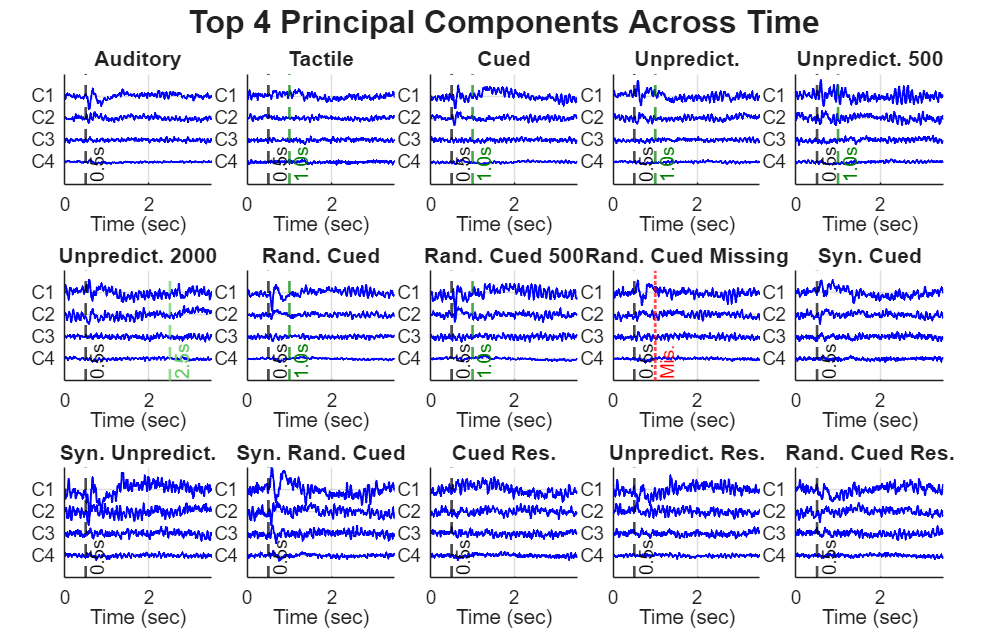


num_comps_plot = 4; % We want to plot the top 5 components
display_comps = 1:1:num_comps_plot;

% Extract condition names (including the split ones like P2_500, P2_2000)
all_cond_names = fieldnames(pca_results);
num_all_conds = length(all_cond_names); 

% Create a wide figure to comfortably fit side-by-side plots
figure('Position',[50 50 2200 1400], 'Name', 'PCA Top 5 Components');
t = tiledlayout(3, 5, 'TileSpacing', 'compact', 'Padding', 'compact');
title(t, 'Top 4 Principal Components Across Time', 'FontSize', 24, 'FontWeight', 'bold');

% Offset: adjust this to pack the component traces tighter or looser vertically
% Components usually have smaller amplitude than raw EEG, so an offset of 5 to 10 is usually good.
comp_offset = 30; 
tick_positions = (num_comps_plot - display_comps) * comp_offset;

% Custom colors for the event lines
dark_green  = [0 0.5 0];
light_green = [0.4 0.8 0.4];

% Loop through all available conditions
for c = 1:num_all_conds
    cond_name = all_cond_names{c};
    
    % Extract [Comp x Time] data
    % pca_results.(cond_name).comp_time has size [TotalComps x Time]
    comp_to_plot = pca_results.(cond_name).comp_time(1:num_comps_plot, :);
    
    nexttile;
    hold on
    
    % 1. Plot the Components
    for comp_idx = 1:num_comps_plot
        % Stack components vertically and use a distinct color (e.g., dark red)
        plot(time_ms_eeg, comp_to_plot(comp_idx, :) + (num_comps_plot - comp_idx)*comp_offset, 'b', 'LineWidth', 1.5);
    end
    
    % 2. Add Vertical Event Lines
    % All conditions get a dashed vertical line at time 0.5 sec (Audio Onset)
    xline(0.5, 'k--', '0.5s', 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
    
    % Condition-specific tactile event lines
    if any(strcmp(cond_name, {'BLT', 'P1', 'P2', 'P2_500', 'P3', 'P3_500'}))
        % Expected tactile onset at 1.0s
        xline(1.0, '--', '1.0s', 'Color', dark_green, 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
        
    elseif contains(cond_name, 'P2_2000')
        % Delayed tactile onset at 2.5s
        xline(2.5, '--', '2.5s', 'Color', light_green, 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
        
    elseif contains(cond_name, 'P3_missing')
        % Missing tactile - draw a red line to indicate where it SHOULD have been
        xline(1.0, 'r:', 'Mis.', 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
    end
    
    hold off
    
    % Fit the X-axis strictly to our cropped time window
    xlim([min(time_ms_eeg), max(time_ms_eeg)]); 
    
    % Set y-limits to frame the stacked traces perfectly
    ylim([-comp_offset, num_comps_plot*comp_offset]);
    
    xlabel('Time (sec)'); 
    % ylabel('Components (stacked)');
    yticks(flip(tick_positions));
    
    % Create string array like {'C1', 'C2', 'C3', 'C4', 'C5'}
    yticklabels(flip(arrayfun(@(x) sprintf('C%d', x), 1:num_comps_plot, 'UniformOutput', false)));
    set(gca,'FontSize',14);
    if strcmp(cond_name, 'BLA')
        plot_title = 'Auditory';
    elseif strcmp(cond_name, 'BLT')
        plot_title = 'Tactile';
    elseif strcmp(cond_name, 'P1')
        plot_title = 'Cued';
    elseif strcmp(cond_name, 'P1_syn')
        plot_title = 'Syn. Cued';
    elseif strcmp(cond_name, 'P1_res')
        plot_title = 'Cued Res.';
    elseif strcmp(cond_name, 'P2')
        plot_title = 'Unpredict.';
    elseif strcmp(cond_name, 'P2_500')
        plot_title = 'Unpredict. 500';
    elseif strcmp(cond_name, 'P2_2000')
        plot_title = 'Unpredict. 2000'; 
    elseif strcmp(cond_name, 'P2_syn')
        plot_title = 'Syn. Unpredict.';
    elseif strcmp(cond_name, 'P2_res')
        plot_title = 'Unpredict. Res.';            
    elseif strcmp(cond_name, 'P3')
        plot_title = 'Rand. Cued';
    elseif strcmp(cond_name, 'P3_500')
        plot_title = 'Rand. Cued 500';
    elseif strcmp(cond_name, 'P3_missing')
        plot_title = 'Rand. Cued Missing';    
    elseif strcmp(cond_name, 'P3_syn')
        plot_title = 'Syn. Rand. Cued';
    elseif strcmp(cond_name, 'P3_res')
        plot_title = 'Rand. Cued Res.';     
    end
    % Format the title cleanly (removes underscores so MATLAB doesn't make subscripts)
    plot_title = strrep(plot_title, '_', ' ');
    title(plot_title, 'FontSize', 16);
    grid on;
end

## 2.01 Visualizing Top 4 Principal Components Overlaid (3 Subplots Total)


disp('Plotting Top 4 PCA Components Overlaid...');

Plotting Top 4 PCA Components Overlaid...


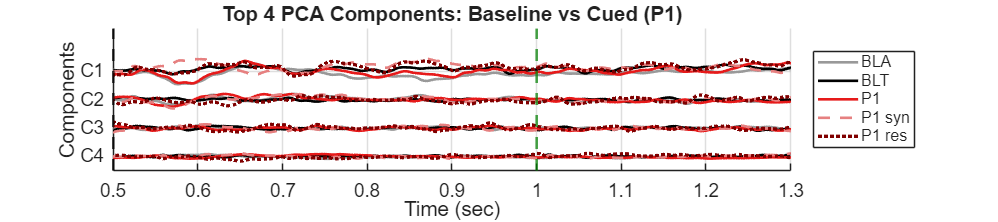

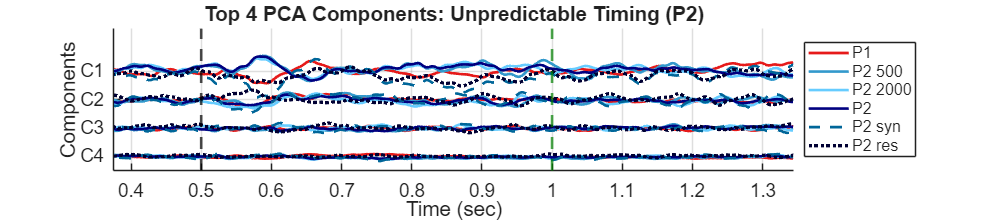

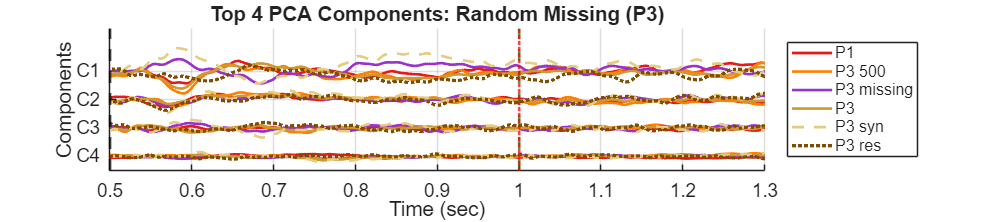


num_comps_plot = 4; % Top 4 components
display_comps = 1:1:num_comps_plot;

% Define the 3 groups for the 3 separate figures
plot_groups = {
    {'BLA', 'BLT', 'P1', 'P1_syn', 'P1_res'},                     % Figure 1
    {'P1', 'P2_500', 'P2_2000', 'P2', 'P2_syn', 'P2_res'},        % Figure 2
    {'P1', 'P3_500', 'P3_missing', 'P3', 'P3_syn', 'P3_res'}      % Figure 3
};

% Set up consistent colors for conditions
% Added lighter shades for _syn and darker shades for _res
color_map = struct(...
    'BLA', [0.6 0.6 0.6], ...       % Gray
    'BLT', [0.0 0.0 0.0], ...       % Light Blue [0.2 0.6 0.8]
    'P1',  [0.9 0.1 0.1], ...       % Red
    'P1_syn', [0.9 0.5 0.5], ...    % Light Red
    'P1_res', [0.5 0.0 0.0], ...    % Dark Red
    'P2_500', [0.2 0.6 0.8], ...    % Bright Green [0.2 0.8 0.2]
    'P2_2000', [0.4 0.8 1.0], ...   % Dark Green [0.0 0.4 0.0]
    'P2', [0.0 0.0 0.5], ...        % 
    'P2_syn', [0.0 0.4 0.6], ...    % Light Olive
    'P2_res', [0.0 0.0 0.2], ...    % Dark Olive
    'P3_500', [1.0 0.5 0.0], ...    % Orange
    'P3_missing', [0.6 0.2 0.8], ...% Purple
    'P3', [0.8 0.6 0.2], ...        % Gold
    'P3_syn', [0.9 0.8 0.5], ...    % Light Gold
    'P3_res', [0.5 0.3 0.0] ...     % Dark Gold
);

% Generous offset so the overlaid variations don't bleed into adjacent components
comp_offset = 40; 
tick_positions = (num_comps_plot - display_comps) * comp_offset;
y_tick_labels = flip(arrayfun(@(x) sprintf('C%d', x), 1:num_comps_plot, 'UniformOutput', false));

% Loop through the 3 groups and create a SEPARATE figure for each
for g = 1:length(plot_groups)
    conds_in_group = plot_groups{g};
    
    % Create a new figure for this specific group
    figure('Position',[50 50 1800 400], 'Name', sprintf('Overlaid PCA Components - Group %d', g));
    hold on;
    
    % Pre-allocate an array to store plot handles for the legend
    h_lines = gobjects(1, length(conds_in_group)); 
    
    for c = 1:length(conds_in_group)
        cond_name = conds_in_group{c};
        
        % Grab color from our map, fallback to random if missing
        if isfield(color_map, cond_name)
            clr = color_map.(cond_name);
        else
            clr = rand(1,3); 
        end
        
        % Dynamic Line Style: Solid for Actual, Dashed for Syn, Dotted for Res
        if contains(cond_name, '_syn')
            l_style = '--';
            l_width = 2.0;
        elseif contains(cond_name, '_res')
            l_style = ':';
            l_width = 2.5; % Slightly thicker to make dotted lines pop
        else
            l_style = '-';
            l_width = 2.0;
        end
        
        % Extract [Comp x Time] data
        comp_to_plot = pca_results.(cond_name).comp_time(1:num_comps_plot, :);
        
        % Plot the stacked components for this specific condition
        for comp_idx = 1:num_comps_plot
            y_offset = (num_comps_plot - comp_idx) * comp_offset;
            
            p = plot(time_ms_eeg, comp_to_plot(comp_idx, :) + y_offset, ...
                'Color', clr, 'LineStyle', l_style, 'LineWidth', l_width);
            
            % Save the plot handle of the very first component to build the legend
            if comp_idx == 1
                h_lines(c) = p;
            end
        end
    end
    
    % Add Vertical Event Lines customized for each figure
    xline(0.5, 'k--', 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom'); % Audio
    
    if g == 1
        xline(1.0, '--', 'Color', [0 0.5 0], 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
        title('Top 4 PCA Components: Baseline vs Cued (P1)', 'FontSize', 22, 'FontWeight', 'bold');
        
    elseif g == 2
        xline(1.0, '--',  'Color', [0 0.5 0], 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
        xline(2.5, '--', 'Color', [0.4 0.8 0.4], 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
        title('Top 4 PCA Components: Unpredictable Timing (P2)', 'FontSize', 22, 'FontWeight', 'bold');
        
    elseif g == 3
        xline(1.0, '--',  'Color', [0 0.5 0], 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
        xline(1.0, 'r:', 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'top');
        title('Top 4 PCA Components: Random Missing (P3)', 'FontSize', 22, 'FontWeight', 'bold');
    end
    
    % Axis Limits and Labels
    xlim([0.5, 1.3]); 
    ylim([-comp_offset*0.5, num_comps_plot*comp_offset + comp_offset*0.5]);
    
    xlabel('Time (sec)', 'FontSize', 16);
    ylabel('Components', 'FontSize', 16);
    yticks(flip(tick_positions));
    yticklabels(y_tick_labels);
    
    set(gca,'FontSize',14);
    grid on;
    
    % Generate a clean legend for exactly the conditions in this figure
    clean_names = strrep(conds_in_group, '_', ' '); % Removes underscores for MATLAB rendering
    legend(h_lines, clean_names, 'Location', 'eastoutside', 'FontSize', 12);
    
    hold off;
end

## 2.1 Cosine between conditions for Auditory ERP for the three time periods: 0-60 ms, 60-200 ms, 200-500 msec after stimulus

% Cosine similarity between BLA and target conditions
disp('Calculating Cosine Similarities...');

Calculating Cosine Similarities...



% Define the time axis in milliseconds
time_ms = time_ms_eeg * 1000; 

% Define relative time windows (post-tactile stimulus) in ms
time_windows_relative = {[0, 60], [60, 200], [200, 500]};
window_names = {'0-60 ms', '60-200 ms', '200-500 ms'};

% The conditions to compare against BLT
compare_conds = {'P1', 'P2_500', 'P2_2000', 'P3_500', 'P3_missing'};
ref_cond = 'BLA';

% We will compare the top 10 principal components
num_comps = 4; 

% Pre-allocate storage for similarities: struct -> window -> matrix
cos_sim_results = struct();

for c = 1:length(compare_conds)
    tgt_cond = compare_conds{c};
    tgt_onset_ms = 500; % for all conditions at 0.5 sec
    
    % Reference onset is always 1000ms for BLT
    ref_onset_ms = 500; 
    
    for w = 1:length(time_windows_relative)
        win = time_windows_relative{w};
        
        % Convert ms windows into discrete sample offsets to avoid floating-point indexing mismatches
        sample_offset_start = round(win(1) / 1000 * fs);
        sample_offset_end   = round(win(2) / 1000 * fs);
        
        % Find the exact center index for the onsets
        ref_idx_center = find(time_ms >= ref_onset_ms, 1);
        tgt_idx_center = find(time_ms >= tgt_onset_ms, 1);
        
        % Create the sample range for this window
        ref_idx_range = (ref_idx_center + sample_offset_start) : (ref_idx_center + sample_offset_end);
        tgt_idx_range = (tgt_idx_center + sample_offset_start) : (tgt_idx_center + sample_offset_end);
        
        % Extract the [comp x time] data for the specified window
        comp_ref = pca_results.(ref_cond).comp_time(1:num_comps, ref_idx_range);
        comp_tgt = pca_results.(tgt_cond).comp_time(1:num_comps, tgt_idx_range);
        
        % Compute pairwise Cosine Similarity
        % pdist2 with 'cosine' returns Cosine Distance (1 - cos(theta)).
        % We feed it [comp x time], so it treats rows (components) as observations
        cos_dist = pdist2(comp_ref, comp_tgt, 'cosine');
        cos_sim_matrix = 1 - cos_dist; % Convert back to similarity [-1 to 1]
        cos_sim_matrix_abs = abs(cos_sim_matrix);
        cos_sim_results.(tgt_cond).(sprintf('win_%d', w)) = cos_sim_matrix_abs;
    end
end

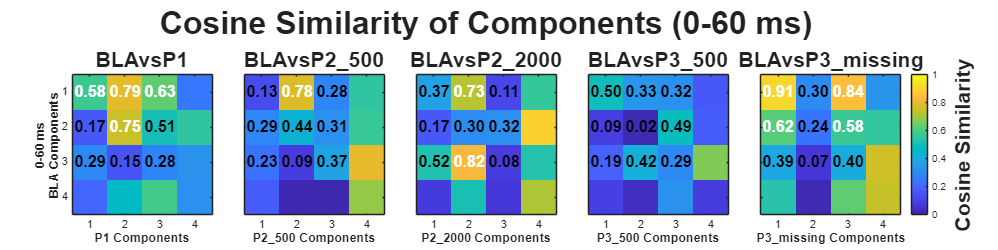

%% Figure 1: 0-60 ms Window
% Create a shorter figure for the single row
figure('Position', [100, 100, 2000, 500], 'Name', 'PCA Cosine Similarity: 0-60ms');
t1 = tiledlayout(1, length(compare_conds), 'TileSpacing', 'compact', 'Padding', 'compact');

w = 1; % Target the 0-60 ms window
for c = 1:length(compare_conds)
    tgt_cond = compare_conds{c};
    nexttile;
    
    sim_mat = cos_sim_results.(tgt_cond).(sprintf('win_%d', w));
    
    imagesc(sim_mat);
    colormap('parula'); 
    caxis([0 1]); 
    axis square;
    xticks(1:num_comps);
    yticks(1:num_comps);
    
    % --- NEW: Overlay values for Top 3 Components ---
    for row = 1:min(3, num_comps)
        for col = 1:min(3, num_comps)
            val = sim_mat(row, col);
            % Use white text for dark backgrounds (high sim), black for light
            if val > 0.55
                txt_color = 'w';
            else
                txt_color = 'k';
            end
            text(col, row, sprintf('%.2f', val), 'Color', txt_color, ...
                'HorizontalAlignment', 'center', 'FontSize', 12, 'FontWeight', 'bold');
        end
    end
    
    % Formatting for a single-row layout
    xlabel(sprintf('%s Components', tgt_cond), 'Interpreter', 'none', 'FontWeight', 'bold');
    title(sprintf('%svs%s', ref_cond, tgt_cond), 'Interpreter', 'none', 'FontSize', 16);
    
    if c == 1
        ylabel(sprintf('%s\n%s Components', window_names{w}, ref_cond), 'Interpreter', 'none', 'FontWeight', 'bold');
    else
        yticklabels({});
    end
    
    if c == length(compare_conds)
        cb = colorbar;
        cb.Label.String = 'Cosine Similarity';
        cb.Label.FontSize = 16;
        cb.Label.FontWeight = 'bold';
    end
end
title(t1, 'Cosine Similarity of Components (0-60 ms)', 'FontSize', 24, 'FontWeight', 'bold');

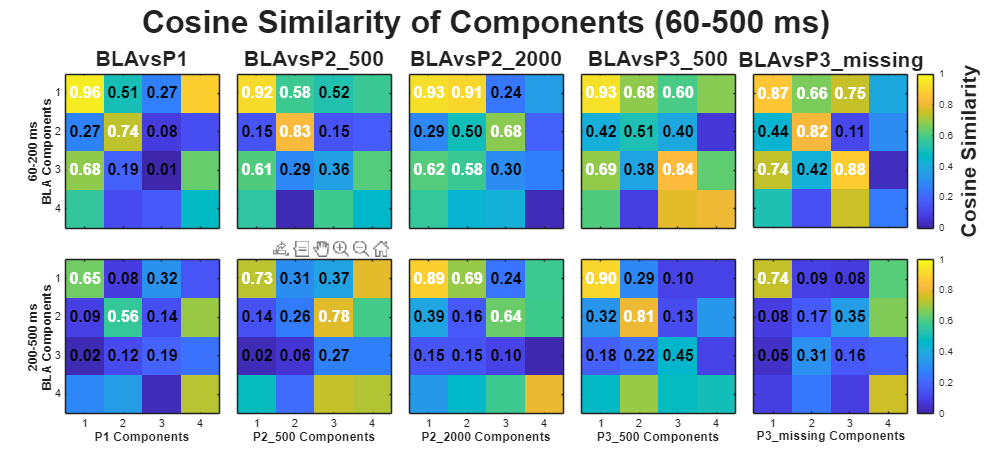



%% Figure 2: 60-200 ms & 200-500 ms Windows
% Create a taller figure for the two rows
figure('Position', [100, 600, 2000, 900], 'Name', 'PCA Cosine Similarity: 60-500ms');
t2 = tiledlayout(2, length(compare_conds), 'TileSpacing', 'compact', 'Padding', 'compact');

windows_to_plot = [2, 3]; % Target the 60-200 and 200-500 ms windows

for w_idx = 1:length(windows_to_plot)
    w = windows_to_plot(w_idx);
    for c = 1:length(compare_conds)
        tgt_cond = compare_conds{c};
        nexttile;
        
        sim_mat = cos_sim_results.(tgt_cond).(sprintf('win_%d', w));
        
        imagesc(sim_mat);
        colormap('parula'); 
        caxis([0 1]); 
        axis square;
        xticks(1:num_comps);
        yticks(1:num_comps);
        
        % --- NEW: Overlay values for Top 3 Components ---
        for row = 1:min(3, num_comps)
            for col = 1:min(3, num_comps)
                val = sim_mat(row, col);
                if val > 0.55
                    txt_color = 'w';
                else
                    txt_color = 'k';
                end
                text(col, row, sprintf('%.2f', val), 'Color', txt_color, ...
                    'HorizontalAlignment', 'center', 'FontSize', 12, 'FontWeight', 'bold');
            end
        end
        
        % Formatting for a multi-row layout
        if w == windows_to_plot(end)
            xlabel(sprintf('%s Components', tgt_cond), 'Interpreter', 'none', 'FontWeight', 'bold');
        else
            xticklabels({});
        end
        
        if c == 1
            ylabel(sprintf('%s\n%s Components', window_names{w}, ref_cond), 'Interpreter', 'none', 'FontWeight', 'bold');
        else
            yticklabels({});
        end
        
        if w == windows_to_plot(1)
            title(sprintf('%svs%s', ref_cond, tgt_cond), 'Interpreter', 'none', 'FontSize', 16);
        end
        
        if c == length(compare_conds)
            cb = colorbar;
            % Only label the colorbar on the top row of this figure for symmetry
            if w == windows_to_plot(1) 
                cb.Label.String = 'Cosine Similarity';
                cb.Label.FontSize = 16;
                cb.Label.FontWeight = 'bold';
            end
        end
    end
end
title(t2, 'Cosine Similarity of Components (60-500 ms)', 'FontSize', 24, 'FontWeight', 'bold');

## Condition comparison vs. P1


% Define the time axis in milliseconds
time_ms = time_ms_eeg * 1000; 

% Define relative time windows (post-stimulus) in ms
time_windows_relative = {[0, 60], [60, 200], [200, 500]};
window_names = {'0-60 ms', '60-200 ms', '200-500 ms'};

% --- NEW CONFIGURATION ---
ref_cond = 'P1'; % P1 is now the reference

% Group the target conditions exactly as requested
group1 = {'BLT', 'BLA'};
group2 = {'P2_500', 'P2_2000', 'P2'};
group3 = {'P3_500', 'P3_missing', 'P3'};

% Combine them into one list for the calculation loop
all_targets = [group1, group2, group3];

% We will compare the top 10 principal components
num_comps = 4; 

% Pre-allocate storage
cos_sim_results = struct();

for c = 1:length(all_targets)
    tgt_cond = all_targets{c};
    
    % Define the absolute onset time for the TARGET condition
    tgt_onset_ms = 500;
    % Reference onset is always 1000ms for P1
    ref_onset_ms = 500; 
    
    for w = 1:length(time_windows_relative)
        win = time_windows_relative{w};
        
        % Convert ms windows into discrete sample offsets
        sample_offset_start = round(win(1) / 1000 * fs);
        sample_offset_end   = round(win(2) / 1000 * fs);
        
        % Find the exact center index for the onsets
        ref_idx_center = find(time_ms >= ref_onset_ms, 1);
        tgt_idx_center = find(time_ms >= tgt_onset_ms, 1);
        
        % Create the sample range for this window
        ref_idx_range = (ref_idx_center + sample_offset_start) : (ref_idx_center + sample_offset_end);
        tgt_idx_range = (tgt_idx_center + sample_offset_start) : (tgt_idx_center + sample_offset_end);
        
        % Extract the [comp x time] data
        comp_ref = pca_results.(ref_cond).comp_time(1:num_comps, ref_idx_range);
        comp_tgt = pca_results.(tgt_cond).comp_time(1:num_comps, tgt_idx_range);
        
        % Compute pairwise Cosine Similarity
        cos_dist = pdist2(comp_ref, comp_tgt, 'cosine');
        cos_sim_matrix = 1 - cos_dist; % Convert distance to similarity [-1 to 1]
        cos_sim_matrix_abs = abs(cos_sim_matrix);
        cos_sim_results.(tgt_cond).(sprintf('win_%d', w)) = cos_sim_matrix_abs;
    end
end


%% 2.2 Heatmaps for cosine similarity (Grouped & Split by Time Window)
disp('Plotting Heatmaps...');

Plotting Heatmaps...


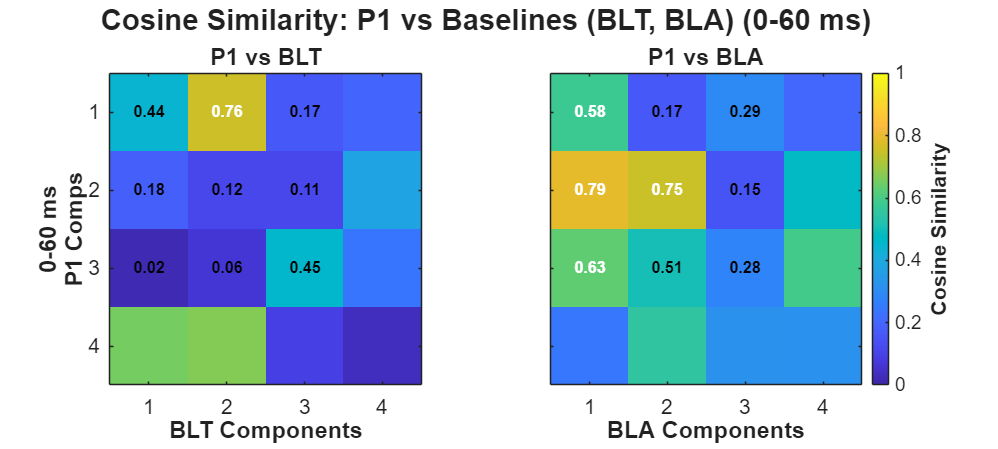

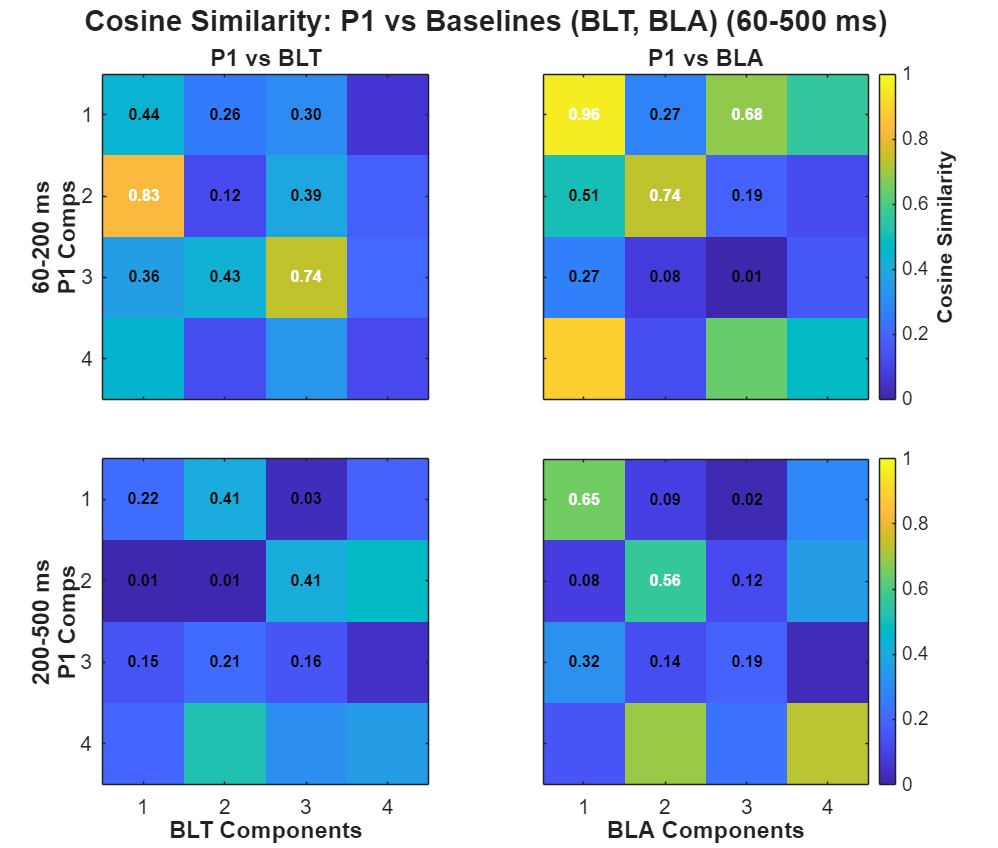

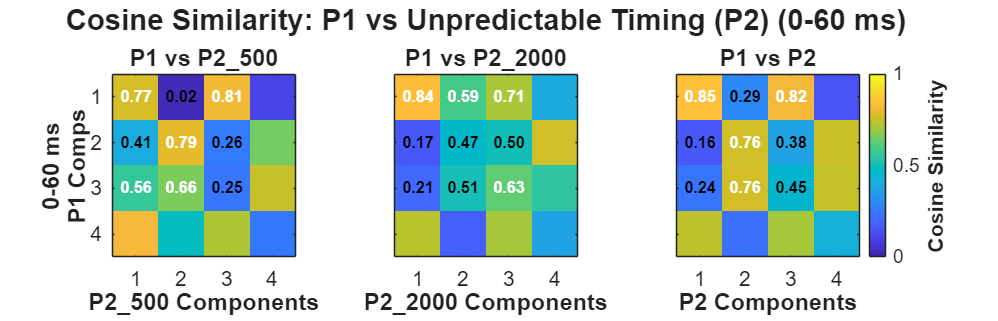

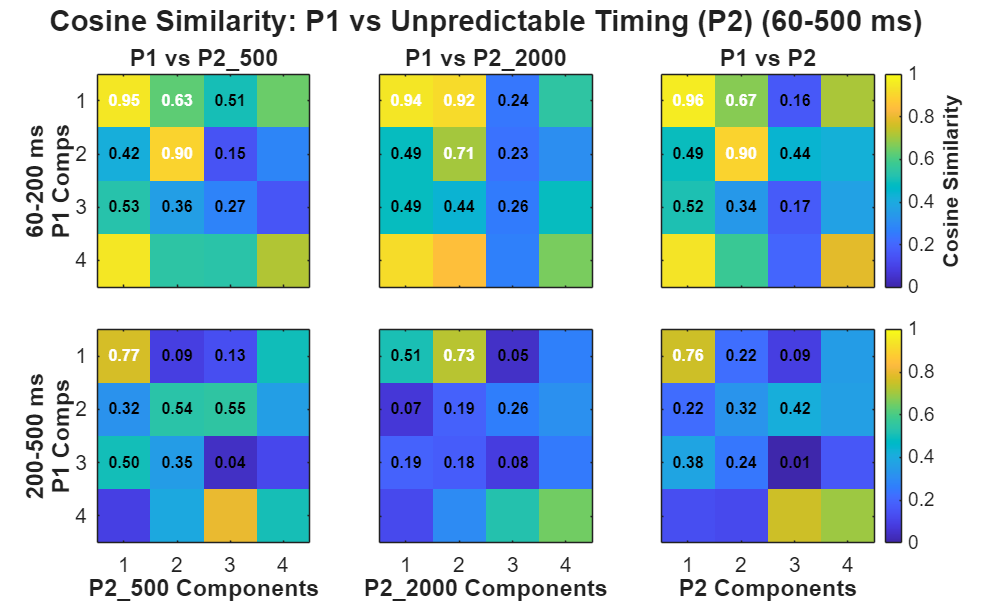

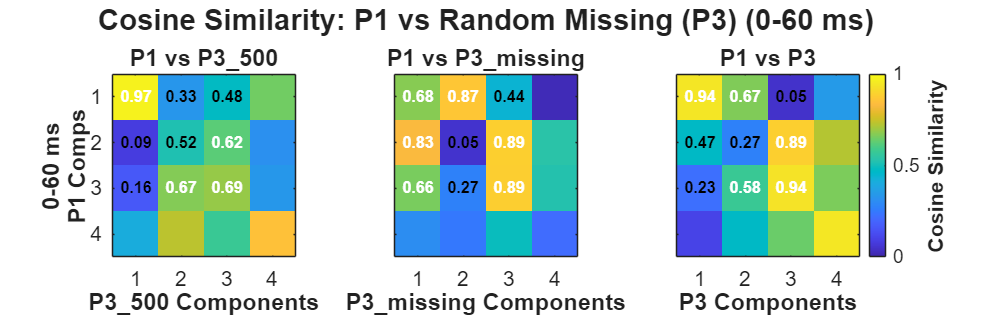

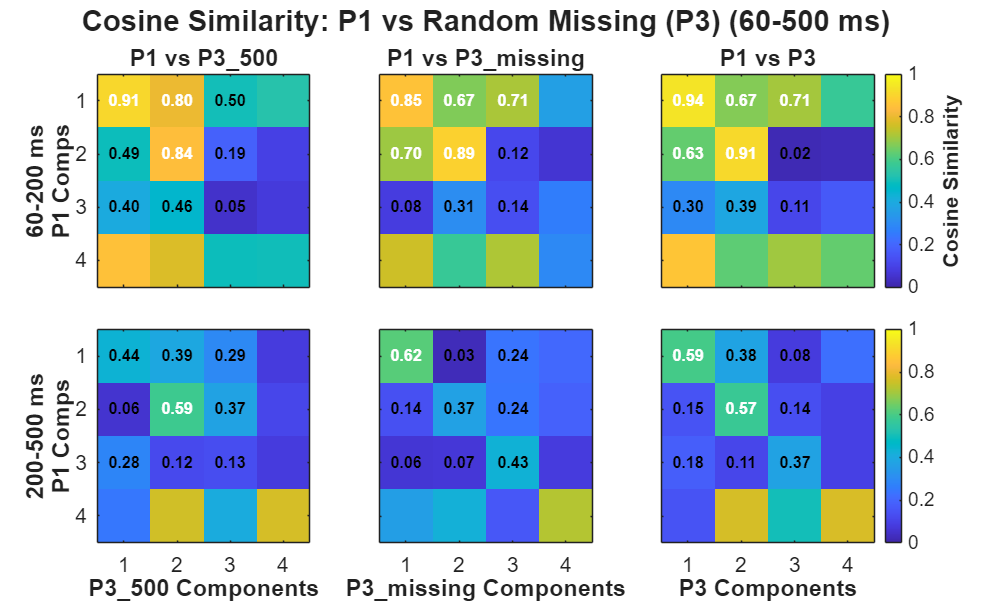


% Organize the groups and titles for the figures
plot_groups = {group1, group2, group3};
group_titles = {
    'P1 vs Baselines (BLT, BLA)', 
    'P1 vs Unpredictable Timing (P2)', 
    'P1 vs Random Missing (P3)'
};

% Loop through each condition group
for g = 1:length(plot_groups)
    current_group = plot_groups{g};
    base_title = group_titles{g};
    
    % Dynamic width based on the number of conditions in this group
    fig_width = 400 * length(current_group) + 200; 
    
    % =====================================================================
    % FIGURE A: 0-60 ms Window (w = 1)
    % =====================================================================
    fig_pos_A = [50 + (g*30), 50 + (g*30), fig_width, 450];
    figure('Position', fig_pos_A, 'Name', sprintf('Group %d: 0-60ms', g));
    
    t1 = tiledlayout(1, length(current_group), 'TileSpacing', 'compact', 'Padding', 'compact');
    w = 1; % Target the 0-60 ms window
    
    for c = 1:length(current_group)
        tgt_cond = current_group{c};
        nexttile;
        
        sim_mat = cos_sim_results.(tgt_cond).(sprintf('win_%d', w));
        
        imagesc(sim_mat);
        colormap('parula'); 
        caxis([0 1]);     
        axis square;
        xticks(1:num_comps);
        yticks(1:num_comps);
        
        % --- Text Overlay for Top 3x3 Components ---
        for row = 1:min(3, num_comps)
            for col = 1:min(3, num_comps)
                val = sim_mat(row, col);
                if val > 0.55
                    txt_color = 'w'; % White text on dark/high-value background
                else
                    txt_color = 'k'; % Black text on light/low-value background
                end
                text(col, row, sprintf('%.2f', val), 'Color', txt_color, ...
                    'HorizontalAlignment', 'center', 'FontSize', 12, 'FontWeight', 'bold');
            end
        end
        
        % Formatting
        xlabel(sprintf('%s Components', tgt_cond), 'Interpreter', 'none', 'FontWeight', 'bold');
        title(sprintf('%s vs %s', ref_cond, tgt_cond), 'Interpreter', 'none', 'FontSize', 16);
        
        if c == 1
            ylabel(sprintf('%s\n%s Comps', window_names{w}, ref_cond), 'Interpreter', 'none', 'FontWeight', 'bold');
        else
            yticklabels({});
        end
        
        if c == length(current_group)
            cb = colorbar;
            cb.Label.String = 'Cosine Similarity';
            cb.Label.FontWeight = 'bold';
            cb.Label.FontSize = 16;
        end
        set(gca,'FontSize',16);
    end
    title(t1, sprintf('Cosine Similarity: %s (0-60 ms)', base_title), 'FontSize', 22, 'FontWeight', 'bold');

    
    % =====================================================================
    % FIGURE B: 60-200 ms and 200-500 ms Windows (w = 2, 3)
    % =====================================================================
    fig_pos_B = [50 + (g*30), 550 + (g*30), fig_width, 850];
    figure('Position', fig_pos_B, 'Name', sprintf('Group %d: 60-500ms', g));
    
    t2 = tiledlayout(2, length(current_group), 'TileSpacing', 'compact', 'Padding', 'compact');
    windows_to_plot = [2, 3]; 
    
    for w_idx = 1:length(windows_to_plot)
        w = windows_to_plot(w_idx);
        for c = 1:length(current_group)
            tgt_cond = current_group{c};
            nexttile;
            
            sim_mat = cos_sim_results.(tgt_cond).(sprintf('win_%d', w));
            
            imagesc(sim_mat);
            colormap('parula'); 
            caxis([0 1]);     
            axis square;
            xticks(1:num_comps);
            yticks(1:num_comps);
            
            % --- Text Overlay for Top 3x3 Components ---
            for row = 1:min(3, num_comps)
                for col = 1:min(3, num_comps)
                    val = sim_mat(row, col);
                    if val > 0.55
                        txt_color = 'w';
                    else
                        txt_color = 'k';
                    end
                    text(col, row, sprintf('%.2f', val), 'Color', txt_color, ...
                        'HorizontalAlignment', 'center', 'FontSize', 12, 'FontWeight', 'bold');
                end
            end
            
            % Formatting
            if w == windows_to_plot(end)
                xlabel(sprintf('%s Components', tgt_cond), 'Interpreter', 'none', 'FontWeight', 'bold');
            else
                xticklabels({});
            end
            
            if c == 1
                ylabel(sprintf('%s\n%s Comps', window_names{w}, ref_cond), 'Interpreter', 'none', 'FontWeight', 'bold');
            else
                yticklabels({});
            end
            
            if w == windows_to_plot(1)
                title(sprintf('%s vs %s', ref_cond, tgt_cond), 'Interpreter', 'none', 'FontSize', 16);
            end
            
            if c == length(current_group)
                cb = colorbar;
                if w == windows_to_plot(1) % Label only the top colorbar for symmetry
                    cb.Label.String = 'Cosine Similarity';
                    cb.Label.FontWeight = 'bold';
                    cb.Label.FontSize = 16;
                end
            end
            set(gca,'FontSize',16);
        end
    end
    title(t2, sprintf('Cosine Similarity: %s (60-500 ms)', base_title), 'FontSize', 22, 'FontWeight', 'bold');
end

## 2.1 Cosine similarity between BLT components and (P1,P2_500,P2_2000,P3_500,P3_missing)

%% 2.1 Cosine similarity between BLT and target conditions
disp('Calculating Cosine Similarities...');

Calculating Cosine Similarities...



% Define the time axis in milliseconds
time_ms = time_ms_eeg * 1000; 

% Define relative time windows (post-tactile stimulus) in ms
time_windows_relative = {[0, 60], [60, 200], [200, 500]};
window_names = {'0-60 ms', '60-200 ms', '200-500 ms'};

% The conditions to compare against BLT
compare_conds = {'P1', 'P2_500', 'P2_2000', 'P3_500', 'P3_missing'};
ref_cond = 'BLT';

% We will compare the top 10 principal components
num_comps = 4; 

% Pre-allocate storage for similarities: struct -> window -> matrix
cos_sim_results = struct();

for c = 1:length(compare_conds)
    tgt_cond = compare_conds{c};
    
    % Define the absolute onset time of the tactile stimulus for the TARGET condition
    if strcmp(tgt_cond, 'P2_2000')
        tgt_onset_ms = 2500; 
    else
        tgt_onset_ms = 1000; % 1.0s for BLT, P1, P2_500, P3_500, and P3_missing expected
    end
    
    % Reference onset is always 1000ms for BLT
    ref_onset_ms = 1000; 
    
    for w = 1:length(time_windows_relative)
        win = time_windows_relative{w};
        
        % Convert ms windows into discrete sample offsets to avoid floating-point indexing mismatches
        sample_offset_start = round(win(1) / 1000 * fs);
        sample_offset_end   = round(win(2) / 1000 * fs);
        
        % Find the exact center index for the onsets
        ref_idx_center = find(time_ms >= ref_onset_ms, 1);
        tgt_idx_center = find(time_ms >= tgt_onset_ms, 1);
        
        % Create the sample range for this window
        ref_idx_range = (ref_idx_center + sample_offset_start) : (ref_idx_center + sample_offset_end);
        tgt_idx_range = (tgt_idx_center + sample_offset_start) : (tgt_idx_center + sample_offset_end);
        
        % Extract the [comp x time] data for the specified window
        comp_ref = pca_results.(ref_cond).comp_time(1:num_comps, ref_idx_range);
        comp_tgt = pca_results.(tgt_cond).comp_time(1:num_comps, tgt_idx_range);
        
        % Compute pairwise Cosine Similarity
        % pdist2 with 'cosine' returns Cosine Distance (1 - cos(theta)).
        % We feed it [comp x time], so it treats rows (components) as observations
        cos_dist = pdist2(comp_ref, comp_tgt, 'cosine');
        cos_sim_matrix = 1 - cos_dist; % Convert back to similarity [-1 to 1]
        cos_sim_matrix_abs = abs(cos_sim_matrix);
        cos_sim_results.(tgt_cond).(sprintf('win_%d', w)) = cos_sim_matrix_abs;
    end
end

## 2.2 Heatmaps for cosine similarity for the three time periods: 0-60 ms, 60-200 ms, 200-300 msec

%% 2.2 Heatmaps for cosine similarity (Split by Time Window)
disp('Plotting Heatmaps...');

Plotting Heatmaps...


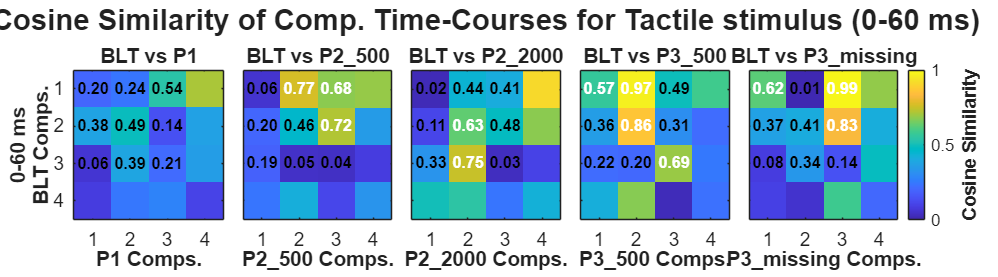


% =====================================================================
% FIGURE 1: 0-60 ms Window (w = 1)
% =====================================================================
% Create a shorter figure for the single row
figure('Position', [100, 100, 1800, 500], 'Name', 'PCA Cosine Similarity: BLT 0-60ms');
t1 = tiledlayout(1, length(compare_conds), 'TileSpacing', 'compact', 'Padding', 'compact');

w = 1; % Target the 0-60 ms window
for c = 1:length(compare_conds)
    tgt_cond = compare_conds{c};
    nexttile;
    
    sim_mat = cos_sim_results.(tgt_cond).(sprintf('win_%d', w));
    
    imagesc(sim_mat);
    colormap('parula'); 
    caxis([0 1]); 
    axis square;
    xticks(1:num_comps);
    yticks(1:num_comps);
    
    % --- Text Overlay for Top 3x3 Components ---
    for row = 1:min(3, num_comps)
        for col = 1:min(3, num_comps)
            val = sim_mat(row, col);
            % Use white text for dark backgrounds (high sim), black for light
            if val > 0.55
                txt_color = 'w';
            else
                txt_color = 'k';
            end
            text(col, row, sprintf('%.2f', val), 'Color', txt_color, ...
                'HorizontalAlignment', 'center', 'FontSize', 12, 'FontWeight', 'bold');
        end
    end
    
    % Formatting for a single-row layout
    xlabel(sprintf('%s Comps.', tgt_cond), 'Interpreter', 'none', 'FontWeight', 'bold');
    title(sprintf('%s vs %s', ref_cond, tgt_cond), 'Interpreter', 'none', 'FontSize', 14);
    
    if c == 1
        ylabel(sprintf('%s\n%s Comps.', window_names{w}, ref_cond), 'Interpreter', 'none', 'FontWeight', 'bold');
    else
        yticklabels({});
    end
    
    if c == length(compare_conds)
        cb = colorbar;
        cb.Label.String = 'Cosine Similarity';
        cb.Label.FontSize = 14;
        cb.Label.FontWeight = 'bold';
    end
    set(gca,'FontSize',14);
end
title(t1, 'Cosine Similarity of Comp. Time-Courses for Tactile stimulus (0-60 ms)', 'FontSize', 22, 'FontWeight', 'bold');

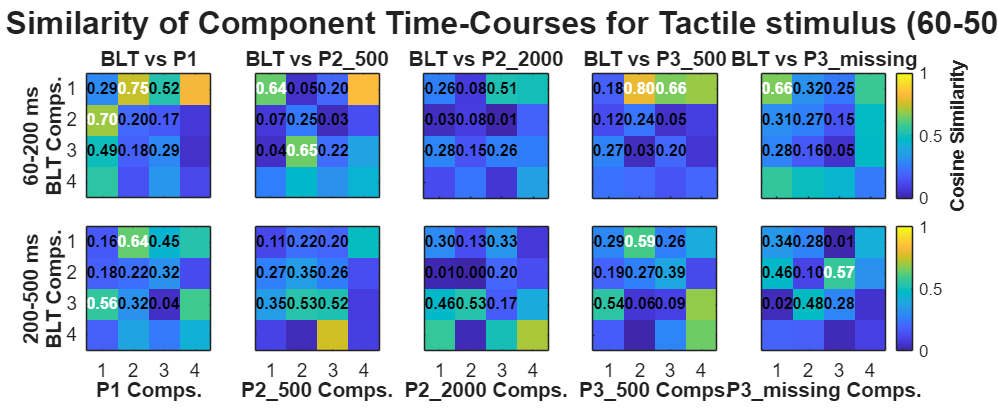



% =====================================================================
% FIGURE 2: 60-200 ms & 200-500 ms Windows (w = 2, 3)
% =====================================================================
% Create a taller figure for the two rows
figure('Position', [100, 600, 2200, 900], 'Name', 'PCA Cosine Similarity: BLT 60-500ms');
t2 = tiledlayout(2, length(compare_conds), 'TileSpacing', 'compact', 'Padding', 'compact');

windows_to_plot = [2, 3]; % Target the 60-200 and 200-500 ms windows

for w_idx = 1:length(windows_to_plot)
    w = windows_to_plot(w_idx);
    for c = 1:length(compare_conds)
        tgt_cond = compare_conds{c};
        nexttile;
        
        sim_mat = cos_sim_results.(tgt_cond).(sprintf('win_%d', w));
        
        imagesc(sim_mat);
        colormap('parula'); 
        caxis([0 1]); 
        axis square;
        xticks(1:num_comps);
        yticks(1:num_comps);
        
        % --- Text Overlay for Top 3x3 Components ---
        for row = 1:min(3, num_comps)
            for col = 1:min(3, num_comps)
                val = sim_mat(row, col);
                if val > 0.55
                    txt_color = 'w';
                else
                    txt_color = 'k';
                end
                text(col, row, sprintf('%.2f', val), 'Color', txt_color, ...
                    'HorizontalAlignment', 'center', 'FontSize', 12, 'FontWeight', 'bold');
            end
        end
        
        % Formatting for a multi-row layout
        if w == windows_to_plot(end)
            xlabel(sprintf('%s Comps.', tgt_cond), 'Interpreter', 'none', 'FontWeight', 'bold');
        else
            xticklabels({});
        end
        
        if c == 1
            ylabel(sprintf('%s\n%s Comps.', window_names{w}, ref_cond), 'Interpreter', 'none', 'FontWeight', 'bold');
        else
            yticklabels({});
        end
        
        if w == windows_to_plot(1)
            title(sprintf('%s vs %s', ref_cond, tgt_cond), 'Interpreter', 'none', 'FontSize', 14);
        end
        
        if c == length(compare_conds)
            cb = colorbar;
            % Only label the colorbar on the top row of this figure for symmetry
            if w == windows_to_plot(1) 
                cb.Label.String = 'Cosine Similarity';
                cb.Label.FontSize = 14;
                cb.Label.FontWeight = 'bold';
            end
        end
        set(gca,'FontSize',14);
    end
end
title(t2, 'Cosine Similarity of Component Time-Courses for Tactile stimulus (60-500 ms)', 'FontSize', 24, 'FontWeight', 'bold');

%% 2.1 Cosine similarity between P1 and target conditions
disp('Calculating Cosine Similarities...');

Calculating Cosine Similarities...



% Define the time axis in milliseconds
time_ms = time_ms_eeg * 1000; 

% Define relative time windows (post-stimulus) in ms
time_windows_relative = {[0, 60], [60, 200], [200, 500]};
window_names = {'0-60 ms', '60-200 ms', '200-500 ms'};

% --- NEW CONFIGURATION ---
ref_cond = 'P1'; % P1 is now the reference

% Group the target conditions exactly as requested
group1 = {'BLT', 'BLA'};
group2 = {'P2_500', 'P2_2000', 'P2'};
group3 = {'P3_500', 'P3_missing', 'P3'};

% Combine them into one list for the calculation loop
all_targets = [group1, group2, group3];

% We will compare the top 10 principal components
num_comps = 4; 

% Pre-allocate storage
cos_sim_results = struct();

for c = 1:length(all_targets)
    tgt_cond = all_targets{c};
    
    % Define the absolute onset time for the TARGET condition
    if strcmp(tgt_cond, 'P2_2000')
        tgt_onset_ms = 2500; 
    else
        tgt_onset_ms = 1000; % 1.0s onset for P1, BLA, BLT, P2_500, P3_500, P3_missing, and the general P2/P3
    end
    
    % Reference onset is always 1000ms for P1
    ref_onset_ms = 1000; 
    
    for w = 1:length(time_windows_relative)
        win = time_windows_relative{w};
        
        % Convert ms windows into discrete sample offsets
        sample_offset_start = round(win(1) / 1000 * fs);
        sample_offset_end   = round(win(2) / 1000 * fs);
        
        % Find the exact center index for the onsets
        ref_idx_center = find(time_ms >= ref_onset_ms, 1);
        tgt_idx_center = find(time_ms >= tgt_onset_ms, 1);
        
        % Create the sample range for this window
        ref_idx_range = (ref_idx_center + sample_offset_start) : (ref_idx_center + sample_offset_end);
        tgt_idx_range = (tgt_idx_center + sample_offset_start) : (tgt_idx_center + sample_offset_end);
        
        % Extract the [comp x time] data
        comp_ref = pca_results.(ref_cond).comp_time(1:num_comps, ref_idx_range);
        comp_tgt = pca_results.(tgt_cond).comp_time(1:num_comps, tgt_idx_range);
        
        % Compute pairwise Cosine Similarity
        cos_dist = pdist2(comp_ref, comp_tgt, 'cosine');
        cos_sim_matrix = 1 - cos_dist; % Convert distance to similarity [-1 to 1]
        cos_sim_matrix_abs = abs(cos_sim_matrix );
        cos_sim_results.(tgt_cond).(sprintf('win_%d', w)) = cos_sim_matrix_abs;
    end
end


%% 2.2 Heatmaps for cosine similarity (Grouped into 3 Figures)
disp('Plotting Heatmaps...');

Plotting Heatmaps...


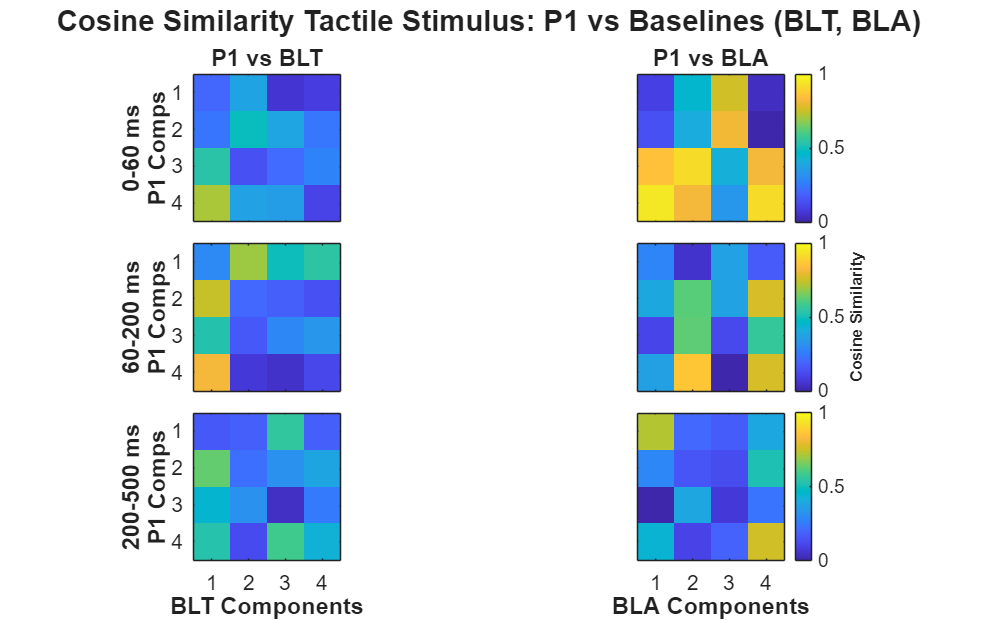

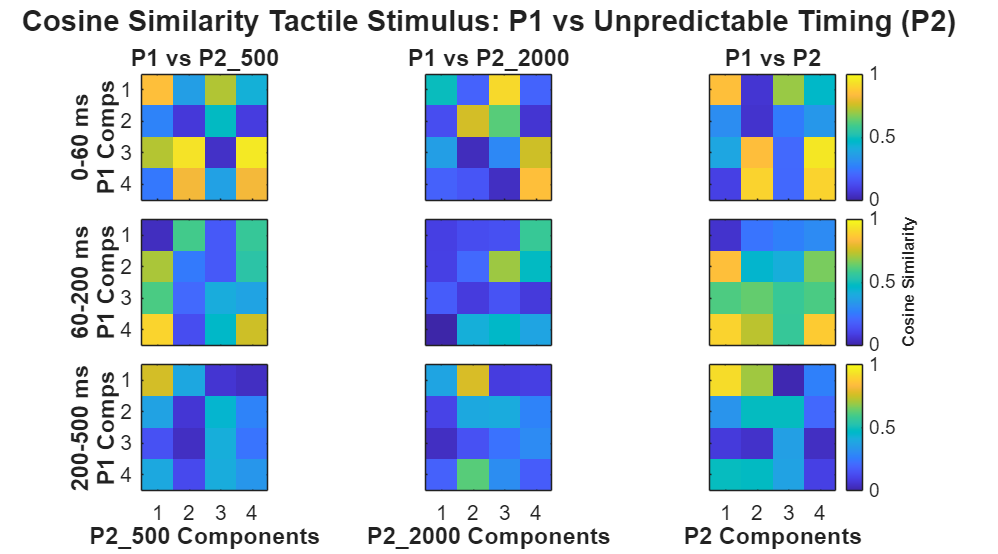

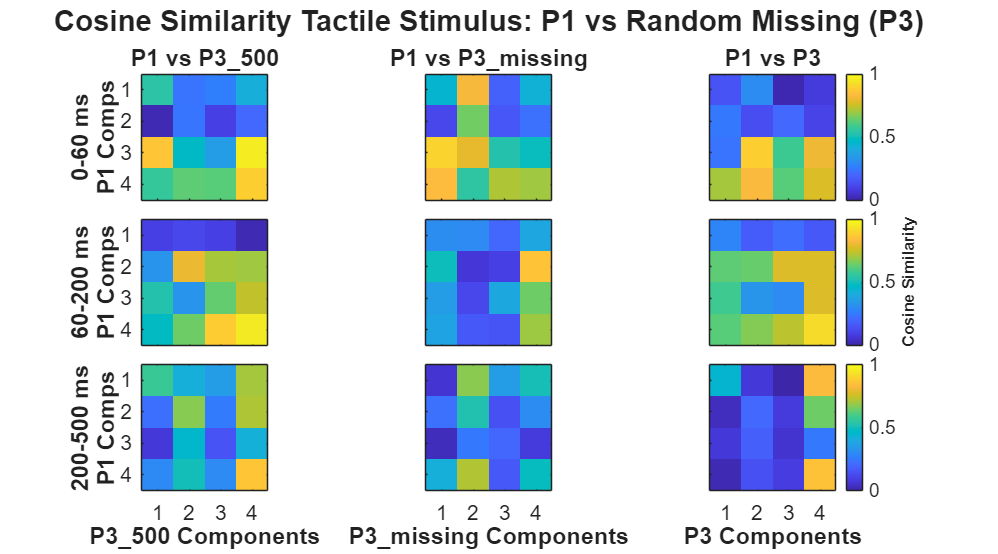


% Organize the groups and titles for the figures
plot_groups = {group1, group2, group3};
group_titles = {
    'Cosine Similarity Tactile Stimulus: P1 vs Baselines (BLT, BLA)', 
    'Cosine Similarity Tactile Stimulus: P1 vs Unpredictable Timing (P2)', 
    'Cosine Similarity Tactile Stimulus: P1 vs Random Missing (P3)'
};

% Generate a separate figure for each group
for g = 1:length(plot_groups)
    current_group = plot_groups{g};
    
    % Offset figure positions slightly so they don't completely overlap on your screen
    fig_pos = [50 + (g*30), 50 + (g*30), 1200 + (length(current_group)*200), 1000];
    figure('Position', fig_pos, 'Name', sprintf('PCA Cosine Sim - Group %d', g));
    
    % Layout: Rows = Time Windows, Columns = Target Conditions
    t = tiledlayout(length(time_windows_relative), length(current_group), 'TileSpacing', 'compact', 'Padding', 'compact');
    
    for w = 1:length(time_windows_relative)
        for c = 1:length(current_group)
            tgt_cond = current_group{c};
            
            nexttile;
            
            % Get the similarity matrix
            sim_mat = cos_sim_results.(tgt_cond).(sprintf('win_%d', w));
            
            % Plot heatmap
            imagesc(sim_mat);
            colormap('parula'); 
            caxis([0 1]);     
            
            % Formatting
            axis square;
            xticks(1:num_comps);
            yticks(1:num_comps);
            
            % X-axis labels strictly on the bottom row
            if w == length(time_windows_relative)
                xlabel(sprintf('%s Components', tgt_cond), 'Interpreter', 'none', 'FontWeight', 'bold');
            else
                xticklabels({});
            end
            
            % Y-axis labels strictly on the leftmost column
            if c == 1
                ylabel(sprintf('%s\n%s Comps', window_names{w}, ref_cond), 'Interpreter', 'none', 'FontWeight', 'bold');
            else
                yticklabels({});
            end
            
            % Titles strictly on the top row
            if w == 1
                title(sprintf('%s vs %s', ref_cond, tgt_cond), 'Interpreter', 'none', 'FontSize', 16);
            end
            
            % Colorbar only on the far right column
            if c == length(current_group)
                cb = colorbar;
                if w == round(length(time_windows_relative)/2) % Label the middle one for symmetry
                    cb.Label.String = 'Cosine Similarity';
                    cb.Label.FontWeight = 'bold';
                    cb.Label.FontSize = 12;
                end
            end
            set(gca,'FontSize',16);
        end
    end
    
    % Add the overarching title for the specific group
    title(t, group_titles{g}, 'FontSize', 22, 'FontWeight', 'bold');
end

## 2.3 Compare Cosine Similarities: Synthetic Null vs. Real Neural Dynamics

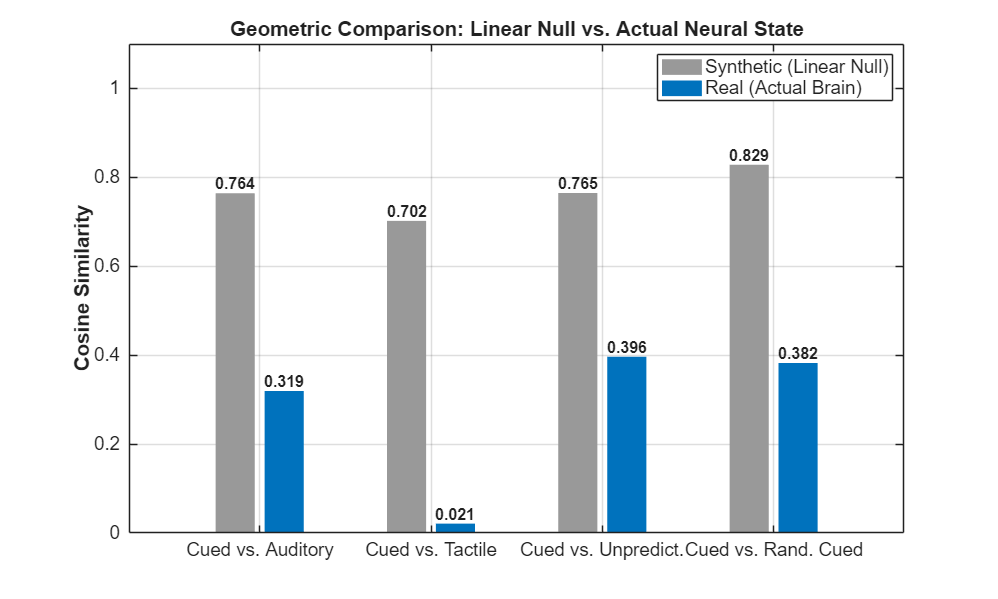

% 1. Define a helper function for Matrix Cosine Similarity
% Using the Frobenius inner product over the flattened 2D arrays
calc_cos_sim = @(A, B) sum(A(:) .* B(:)) / (sqrt(sum(A(:).^2)) * sqrt(sum(B(:).^2)));

% 2. Calculate the Similarities
% --- Comparison 1: Integration (P1 vs Baseline Modalities) ---
sim_SynP1_BLA  = calc_cos_sim(data_avg.P1_syn, data_avg.BLA);
sim_RealP1_BLA = calc_cos_sim(data_avg.P1, data_avg.BLA);

sim_SynP1_BLT  = calc_cos_sim(data_avg.P1_syn, data_avg.BLT);
sim_RealP1_BLT = calc_cos_sim(data_avg.P1, data_avg.BLT);

% --- Comparison 2: Predictability (P1 vs P2) ---
sim_SynP1_SynP2   = calc_cos_sim(data_avg.P1_syn, data_avg.P2_syn);
sim_RealP1_RealP2 = calc_cos_sim(data_avg.P1, data_avg.P2);

% --- Comparison 3: Predictability (P1 vs P3) ---
sim_SynP1_SynP3   = calc_cos_sim(data_avg.P1_syn, data_avg.P3_syn);
sim_RealP1_RealP3 = calc_cos_sim(data_avg.P1, data_avg.P3);

% 3. Aggregate data for the Bar Chart
% Rows: [BLA, BLT, P2, P3], Columns: [Synthetic, Real]
sim_matrix = [
    sim_SynP1_BLA,  sim_RealP1_BLA;
    sim_SynP1_BLT,  sim_RealP1_BLT;
    sim_SynP1_SynP2, sim_RealP1_RealP2;
    sim_SynP1_SynP3, sim_RealP1_RealP3
];

% 4. Visualization
figure('Position', [100, 100, 1000, 600]);

% Create categorical labels and ensure they stay in this exact order
categories = {'Cued vs. Auditory', 'Cued vs. Tactile', 'Cued vs. Unpredict.', 'Cued vs. Rand. Cued'};
x_labels = categorical(categories);
x_labels = reordercats(x_labels, categories);

% Plot grouped bars
b = bar(x_labels, sim_matrix, 'grouped');

% Styling the bars for contrast
b(1).FaceColor = [0.6 0.6 0.6]; % Gray for Synthetic Null
b(2).FaceColor = [0 0.4470 0.7410]; % Blue for Actual Brain
b(1).EdgeColor = 'none';
b(2).EdgeColor = 'none';

% Add values on top of the bars for precision
for i = 1:2
    xtips = b(i).XEndPoints;
    ytips = b(i).YEndPoints;
    labels = string(round(b(i).YData, 3));
    text(xtips, ytips, labels, 'HorizontalAlignment', 'center', ...
        'VerticalAlignment', 'bottom', 'FontSize', 12, 'FontWeight', 'bold');
end

% Formatting the plot
ylim([0, 1.1]); % Cosine similarity max is 1, leave room for text
ylabel('Cosine Similarity', 'FontSize', 16, 'FontWeight', 'bold');
title('Geometric Comparison: Linear Null vs. Actual Neural State', 'FontSize', 20, 'FontWeight', 'bold');

legend({'Synthetic (Linear Null)', 'Real (Actual Brain)'}, 'Location', 'northeast', 'FontSize', 14);
set(gca, 'FontSize', 14);
grid on;